
% Define the updated colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
    0.7 0.5 0.8;  % TGP (lightPurple)
    0.85 0.3 0.5; % WTO (Reddish Pink)
    0.5 0.1 0.4]; % TGO (Dark Purple)


% Labels for each group
groupLabels = {'WTP (Pink-Orange)', 'TGP (Blue-Purple)', ...
               'WTO (Reddish-Orange)', 'TGO (Dark Blue-Purple)'};

% Plot the colors as a simple bar graph
figure;
hold on;
for i = 1:length(groupColors)
    bar(i, 1, 'FaceColor', groupColors(i,:), 'EdgeColor', 'k');
end
hold off;

% Adjust the plot appearance
set(gca, 'XTick', 1:length(groupLabels), 'XTickLabel', groupLabels, ...
    'XTickLabelRotation', 30, 'FontSize', 12, 'YTick', []);
ylim([0 1]);
box off;
title('Updated Group Colors');


# Making Weights table

% Define data
genoType = { 'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT';
             'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG';
             'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT'; 'WT';
             'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG'; 'TG' };

Hormone = { 'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro';
            'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro'; 'pro';
            'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX';
            'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX'; 'OVX' };

weight = [ 245; 223; 229; 212; 233; 216; 217;
           251; 276; 262; 247; 247; 239; 260; 221; 279;
           245; 252; 272; 285; 269; 284; 249; 242; 247;
           289; 289; 280; 308; 306; 287; 298; 265; 268; 249 ];
       
UterusWeight = [ 0.5158; 0.5633; 0.9651; NaN; 0.5404; NaN; 1.2522;
                 0.53; 0.5723; 0.5634; 0.6853; 0.9915; 0.8296; 0.566; 0.4942; 0.7707;
                 0.211; 0.1183; 0.1372; 0.1133; 0.1445; 0.0817; 0.1501; 0.1266; 0.0923;
                 0.1402; 0.1; 0.1553; 0.2344; 0.1622; 0.1037; 0.1025; 0.1625; 0.1293; 0.1053 ];

% Calculate Uterus Weight / Body Weight
UterusWeightRatio = UterusWeight ./ weight;

   

% Create table
uteriWeights = table(genoType, Hormone, weight, UterusWeight, UterusWeightRatio);


# two way ANOVA for weights



%% Two-Way ANOVA for Uterus Weight Ratio
% Remove rows with missing uterus weight ratio data
validIdx = ~isnan(uteriWeights.UterusWeightRatio);
ratios = uteriWeights.UterusWeightRatio(validIdx);
genoRatio = uteriWeights.genoType(validIdx);
hormoneRatio = uteriWeights.Hormone(validIdx);

% Run two-way ANOVA with interaction for uterus weight ratio
[p_ratio, tbl_ratio, stats_ratio] = anovan(ratios, {genoRatio, hormoneRatio}, ...
    'model', 'interaction', 'varnames', {'Genotype', 'Hormone'});

% Display the results in the command window
disp('Two-way ANOVA for Uterus Weight Ratio:');
disp(tbl_ratio);

% Optional: Perform post-hoc multiple comparisons
figure;
multcompare(stats_ratio);
title('Post-hoc Comparisons for Uterus Weight Ratio');

%% Two-Way ANOVA for Body Weight
% Run two-way ANOVA with interaction for body weight
[p_weight, tbl_weight, stats_weight] = anovan(uteriWeights.weight, {uteriWeights.genoType, uteriWeights.Hormone}, ...
    'model', 'interaction', 'varnames', {'Genotype', 'Hormone'});

% Display the results in the command window
disp('Two-way ANOVA for Body Weight:');
disp(tbl_weight);

% Optional: Perform post-hoc multiple comparisons
figure;
multcompare(stats_weight);
title('Post-hoc Comparisons for Body Weight');


# body weights box plots

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)


% Define group order and rename appropriately
groupLabels = {'WTP', 'TGP', 'WTO', 'TGO'};
groupNames = replace(strcat(genoType, Hormone), ...
                     {'WTpro', 'TGpro', 'WTOVX', 'TGOVX'}, ...
                     {'WTP', 'TGP', 'WTO', 'TGO'});

groups = categorical(groupNames, groupLabels, 'Ordinal', true);

% Create boxplot
figure;
h = boxplot(weight, groups, 'Symbol', 'o');
xlabel('Group');
ylabel('Weight (g)');
title('Body Weight Distribution by Group');


% Apply colors to the box plots
hBox = findobj(gca, 'Tag', 'Box');
for j = 1:length(hBox)
    set(hBox(j), 'LineWidth', 1.5);
    patch(get(hBox(j), 'XData'), get(hBox(j), 'YData'), groupColors(end-j+1, :), 'FaceAlpha', 0.5, 'EdgeColor', groupColors(end-j+1, :));
end

% Adjust error bar colors to match box colors
hWhisker = findobj(gca, 'Tag', 'Whisker');
hMedian = findobj(gca, 'Tag', 'Median');
hCap = findobj(gca, 'Tag', 'Cap');
for j = 1:length(hWhisker)
    set(hWhisker(j), 'Color', groupColors(ceil(j / 2), :));
end
for j = 1:length(hMedian)
    set(hMedian(j), 'Color', groupColors(ceil(j / 2), :));
end
for j = 1:length(hCap)
    set(hCap(j), 'Color', groupColors(ceil(j / 2), :));
end



%%%%Body weight ANOVA
Y = uteriWeights.weight;
G1 = grp2idx(uteriWeights.genoType); % Convert to numeric indices
G2 = grp2idx(uteriWeights.Hormone); % Convert to numeric indices

% Perform two-way ANOVA
[p, tbl, stats] = anovan(Y, {G1, G2}, 'model', 'interaction', ...
    'varnames', {'GenoType', 'Hormone'});

% Display the ANOVA table
disp(tbl)



# uterus weights box plots

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Define group order and rename appropriately
groupLabels = {'WTP', 'TGP', 'WTO', 'TGO'};
groupNames = replace(strcat(genoType, Hormone), ...
                     {'WTpro', 'TGpro', 'WTOVX', 'TGOVX'}, ...
                     {'WTP', 'TGP', 'WTO', 'TGO'});

groups = categorical(groupNames, groupLabels, 'Ordinal', true);

% Create boxplot
figure;
h = boxplot(UterusWeightRatio, groups, 'Symbol', 'o');
xlabel('Group');
ylabel('Normalized Uterus Weight');
title('Normalized Uterus Weight');


% Apply colors to the box plots
hBox = findobj(gca, 'Tag', 'Box');
for j = 1:length(hBox)
    set(hBox(j), 'LineWidth', 1.5);
    patch(get(hBox(j), 'XData'), get(hBox(j), 'YData'), groupColors(end-j+1, :), 'FaceAlpha', 0.5, 'EdgeColor', groupColors(end-j+1, :));
end

% Adjust error bar colors to match box colors
hWhisker = findobj(gca, 'Tag', 'Whisker');
hMedian = findobj(gca, 'Tag', 'Median');
hCap = findobj(gca, 'Tag', 'Cap');
for j = 1:length(hWhisker)
    set(hWhisker(j), 'Color', groupColors(ceil(j / 2), :));
end
for j = 1:length(hMedian)
    set(hMedian(j), 'Color', groupColors(ceil(j / 2), :));
end
for j = 1:length(hCap)
    set(hCap(j), 'Color', groupColors(ceil(j / 2), :));
end

Y = uteriWeights.UterusWeightRatio;
G1 = grp2idx(uteriWeights.genoType); % Convert to numeric indices
G2 = grp2idx(uteriWeights.Hormone); % Convert to numeric indices

% Perform two-way ANOVA
[p, tbl, stats] = anovan(Y, {G1, G2}, 'model', 'interaction', ...
    'varnames', {'GenoType', 'Hormone'});

% Display the ANOVA table
disp(tbl)


# Confidence BABY

Getting outliers IQR from BL

groups = unique(aallBLAves.group); % Get unique groups
outlierIdx = false(size(aallBLAves.spikePtime)); % Preallocate logical index

for i = 1:length(groups)
    % Get indices for the current group
    idx = aallBLAves.group == groups(i);
    
    % Extract spikePtime values for the current group
    data = aallBLAves.spikePtime(idx);
    
    % Compute Q1, Q3, and IQR
    Q1 = prctile(data, 25);
    Q3 = prctile(data, 75);
    IQR = Q3 - Q1;
    
    % Define outlier threshold
    lowerBound = Q1 - 1.5 * IQR;
    upperBound = Q3 + 1.5 * IQR;
    
    % Identify outliers
    outlierIdx(idx) = (data < lowerBound) | (data > upperBound);
end

% Create a new table without outliers
cleanedAallBLAves = aallBLAves(~outlierIdx, :);




% Identify outlier units
outlierUnits = unique(aallBLAves.unitID(outlierIdx));

% Remove outlier units from other tables
cleanedAallFSAves = aallFsAves(~ismember(aallFsAves.unitID, outlierUnits), :);
cleanedAallRestAves = aallRestAves(~ismember(aallRestAves.unitID, outlierUnits), :);
cleanedAallSpikes = aallSpikes(~ismember(aallSpikes.unitID, outlierUnits), :);


# SpikeHeat Map sorted by FR within group

% Extract unique unit list from aallSpikes
unitlist = unique(cleanedAallSpikes.unitID);

% Assign correct group per unit using indexing
[~, unitIdx] = ismember(unitlist, cleanedAallSpikes.unitID);
groupPerUnit = cleanedAallSpikes.group(unitIdx); % Extract corresponding group

% Convert groupPerUnit to categorical
groupPerUnit = cellstr(groupPerUnit);

% Extract spikePtime from aallBLAves based on unitID
spikePtimeValues = nan(size(unitlist)); % Initialize
for i = 1:numel(unitlist)
    matchIdx = find(cleanedAallBLAves.unitID == unitlist(i), 1); % Match unit to BLAves
    if ~isempty(matchIdx)
        spikePtimeValues(i) = cleanedAallBLAves.spikePtime(matchIdx);
    end
end

% Convert extracted data into a table
unitData = table(unitlist, groupPerUnit, spikePtimeValues, ...
                 'VariableNames', {'unitlist', 'groupPerUnit', 'spikePtime'});

% Convert groups to categorical with correct order
unitData.groupPerUnit = categorical(unitData.groupPerUnit, {'WTP', 'TGP', 'WTO', 'TGO'});

% Sort first by group, then by descending spikePtime
unitData = sortrows(unitData, ["groupPerUnit", "spikePtime"], ["ascend", "descend"]);

% Extract sorted unit list
sortedUnitlist = unitData.unitlist;
numUnits = numel(sortedUnitlist);

% Extract spike trains for each sorted unit
spiketrain = cell(numUnits, 1);
for i = 1:numUnits
    spiketrain{i} = cleanedAallSpikes.adjustedTimestamp(strcmp(cleanedAallSpikes.unitID, sortedUnitlist{i})) / 60; % Convert to minutes
end

% Define dynamic edges and bin interval for heatmap (5-second bins in minutes)
minTime = min(cellfun(@min, spiketrain));
maxTime = max(cellfun(@max, spiketrain));

% Remove bins between 889–900 seconds (14.82 - 15 minutes)
filteredEdges = minTime:(5/60):14.82;  % Stop before 14.82 mins
filteredEdges = [filteredEdges, (15:5/60:maxTime)]; % Resume at 15 minutes
dynamicEdges = unique(filteredEdges);  % Ensure no duplicate bins
binInterval = dynamicEdges(2) - dynamicEdges(1);  % Bin width in minutes
numBins = numel(dynamicEdges) - 1;  % Number of bins is one less than the number of edges

% Create heatmap for sorted units (convert spike times to minutes)
heatmap = zeros(numUnits, numBins);
for i = 1:numUnits
    heatmap(i, :) = histcounts(spiketrain{i}, dynamicEdges); % Already in minutes
end

% Plot heatmap with dynamic color limits
figure;
imagesc(heatmap);
colormap('jet');
colorbar;
caxis([0 100]); % Fix color scale max at 100


% Add vertical transition lines for time periods
hold on;
xTicks = [0, 10, 15, 25, 50, 600/60, 1500/60, 3300/60]; % All in minutes
xTicks = unique(xTicks(xTicks >= minTime & xTicks <= maxTime)); % Remove duplicates
xTickBinPositions = interp1(dynamicEdges, 1:numel(dynamicEdges), xTicks, 'nearest');
for i = 1:numel(xTickBinPositions)
    line([xTickBinPositions(i), xTickBinPositions(i)], [1, numUnits], 'Color', 'w', 'LineWidth', 1.5);
end

% Add horizontal group transition lines
[~, ~, groupIdx] = unique(unitData.groupPerUnit, 'stable'); % Group index for each row
groupTransitions = find(diff(groupIdx) ~= 0);
for i = 1:numel(groupTransitions)
    line([0, numBins], [groupTransitions(i) + 0.5, groupTransitions(i) + 0.5], 'Color', 'w', 'LineWidth', 2, 'LineStyle', '-');
end

% Format axes
set(gca, 'XLim', [0 numBins], ...
         'XTick', xTickBinPositions, ...
         'XTickLabel', round(xTicks, 2), ...
         'YTick', 1:numUnits, ...
         'YTickLabel', sortedUnitlist, ...
         'YLim', [0 numUnits + 1], ...
         'FontName', 'Arial', 'FontSize', 24);

xlabel('Time (mins)');
ylabel('Unit ID');
title('Firing Activity Sorted by FiringRate', 'FontName', 'Arial', 'FontSize', 24);
hold off;



# Line Graph

% Extract unique units and spike times from the adjusted timestamps column
units = cleanedAallSpikes.unitID;
spikeTimes = cleanedAallSpikes.adjustedTimestamp;
group = cleanedAallSpikes.group;
timeSeconds = cleanedAallSpikes.adjustedTimestamp;
timeMinutes = timeSeconds / 60;

% Extract unique unit list
unitlist = unique(units);

% Correctly group units based on the 'group' column
isWTP = strcmp(group, 'WTP');
isTGP = strcmp(group, 'TGP');
isWTO = strcmp(group, 'WTO');
isTGO = strcmp(group, 'TGO');

% Identify units belonging to each group
unitsWTP = unitlist(ismember(unitlist, units(isWTP)));
unitsTGP = unitlist(ismember(unitlist, units(isTGP)));
unitsWTO = unitlist(ismember(unitlist, units(isWTO)));
unitsTGO = unitlist(ismember(unitlist, units(isTGO)));

% Reorganize unitlist and spiketrain based on corrected group order
sortedUnitlist = [unitsWTP; unitsTGP; unitsWTO; unitsTGO];
numUnits = numel(sortedUnitlist);
spiketrain = cell(numUnits, 1);

% Extract spike trains for each sorted unit
for i = 1:numUnits
    spiketrain{i} = spikeTimes(units == sortedUnitlist(i));
end

% Create a table to show unit IDs grouped by group
maxGroupSize = max([length(unitsWTP), length(unitsTGP), length(unitsWTO), length(unitsTGO)]);
unitGroupTable = table(cell(maxGroupSize,1), cell(maxGroupSize,1), cell(maxGroupSize,1), cell(maxGroupSize,1),...
    'VariableNames',{'WTP','TGP','WTO','TGO'});

unitGroupTable.WTP(1:length(unitsWTP)) = num2cell(unitsWTP);
unitGroupTable.TGP(1:length(unitsTGP)) = num2cell(unitsTGP);
unitGroupTable.WTO(1:length(unitsWTO)) = num2cell(unitsWTO);
unitGroupTable.TGO(1:length(unitsTGO)) = num2cell(unitsTGO);

% Define dynamic edges and bin interval for line graph (5-second bins in minutes)
minTime = min(timeMinutes);
maxTime = max(timeMinutes);
dynamicEdges = minTime:60/60:maxTime;  % 5-second intervals in minutes
binInterval = dynamicEdges(2) - dynamicEdges(1);  % Bin width in minutes
numBins = numel(dynamicEdges) - 1;  % Number of bins is one less than the number of edges

% Create firing rates for sorted units (convert spike times to minutes)
firingRates = zeros(numUnits, numBins);
for i = 1:numUnits
    counts = histcounts(spiketrain{i} / 60, dynamicEdges); % Convert to minutes
    firingRates(i, :) = counts / (binInterval * 60); % Normalize by bin width to get firing rate in Hz
end

% Calculate average firing rate per group
groupLabels = {'WTP', 'TGP', 'WTO', 'TGO'};
groupRates = [mean(firingRates(ismember(sortedUnitlist, unitsWTP), :), 1, 'omitnan'); 
              mean(firingRates(ismember(sortedUnitlist, unitsTGP), :), 1, 'omitnan');
              mean(firingRates(ismember(sortedUnitlist, unitsWTO), :), 1, 'omitnan');
              mean(firingRates(ismember(sortedUnitlist, unitsTGO), :), 1, 'omitnan')];

% Plot raw firing rates
figure;
hold on;
plot(dynamicEdges(1:end-1), groupRates(1, :), 'LineWidth', 2, 'Color', [1 0.75 0.8]);
plot(dynamicEdges(1:end-1), groupRates(2, :), 'LineWidth', 2, 'Color', [0.7 0.5 0.7]);
plot(dynamicEdges(1:end-1), groupRates(3, :), 'LineWidth', 2, 'Color', [0.85 0.3 0.5]);
plot(dynamicEdges(1:end-1), groupRates(4, :), 'LineWidth', 2, 'Color', [0.5 0.1 0.4]);

% Add vertical lines for specific times
xline(10, 'k', 'LineWidth', 1.5);
xline(15, 'k', 'LineWidth', 1.5);
xline(25, 'k', 'LineWidth', 1.5);
xline(50, 'k', 'LineWidth', 1.5);

% Set axis limits and labels for better visualization
xlabel('Time (mins)');
ylabel('Firing Rate (Hz)');
ylim([0 max(groupRates, [], 'all') * 1.1]);
legend(groupLabels, 'Location', 'northeastoutside');
set(gca, 'FontName', 'Arial', 'FontSize', 24);
set(gca, 'XAxisLocation', 'top');
xlim([0 maxTime]);
xticks(0:5:maxTime);
hold off;

# Bar graph for FR with dots

% Define the correct order of groups as a string array
groupOrder = ["WTP", "TGP", "WTO", "TGO"];

% If 'groups' is already a string array, you can directly use it.
% Otherwise, if it's categorical, you can convert it to a string array.
groups = string(groups);

% Determine the order indices based on the defined order
[~, orderIdx] = ismember(groupOrder, groups);

% Reorder groups based on the defined order
groups = groups(orderIdx);
numGroups = length(groups);

% Preallocate arrays for means and standard errors
means = zeros(numGroups, 1);
SEs = zeros(numGroups, 1);

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Calculate mean and standard error for each group
for i = 1:numGroups
    % Compare by converting cleanedAallBLAves.group to string if necessary
    idx = string(cleanedAallBLAves.group) == groups(i);
    data = cleanedAallBLAves.spikePtime(idx);

    means(i) = mean(data);
    SEs(i) = std(data) / sqrt(sum(idx)); % Standard error
end

% Create bar plot with error bars
figure;
barHandle = bar(1:numGroups, means);
barHandle.FaceColor = 'flat';
for i = 1:numGroups
    barHandle.CData(i, :) = groupColors(i, :);
end
hold on;
errorbar(1:numGroups, means, SEs, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Overlay individual data points with slight horizontal jitter
for i = 1:numGroups
    idx = string(cleanedAallBLAves.group) == groups(i);
    data = cleanedAallBLAves.spikePtime(idx);
    % Add slight horizontal jitter so points don't overlap
    x = i + (rand(size(data)) - 0.5) * 0.7;
    plot(x, data, 'k.', 'MarkerSize', 8);
end
hold off;

% Set x-axis labels and formatting
xticks(1:numGroups);
xticklabels(groups);
%xlabel('Group');
ylabel('Firing Rate (Hz)');
%title('Spikes/Time');
grid on;

% Improve appearance
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
box on;



# Bar graph for ISI with dots

% Define the correct order of groups
groupOrder = {'WTP', 'TGP', 'WTO', 'TGO'};
[~, orderIdx] = ismember(groupOrder, groups);

% Reorder based on the defined order
groups = groups(orderIdx);
numGroups = length(groups);

% Preallocate arrays for means and standard errors
means = zeros(numGroups, 1);
SEs = zeros(numGroups, 1);

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Calculate mean and standard error for each group
for i = 1:numGroups
    idx = cleanedAallBLAves.group == groups(i);
    data = cleanedAallBLAves.ISI(idx);

    means(i) = mean(data);
    SEs(i) = std(data) / sqrt(sum(idx)); % Standard error
end

% Create bar  with error bars
figure;
barHandle = bar(1:numGroups, means);
for i = 1:numGroups
    barHandle.FaceColor = 'flat';
    barHandle.CData(i, :) = groupColors(i, :);
end
hold on;
errorbar(1:numGroups, means, SEs, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Overlay individual data points as tiny black dots
for i = 1:numGroups
    idx = cleanedAallBLAves.group == groups(i);
    data = cleanedAallBLAves.ISI(idx);
    % Add slight horizontal jitter so points don't overlap exactly
    x = i + (rand(size(data)) -0.5) * 0.7;
    plot(x, data, 'k.', 'MarkerSize', 8);
end
hold off;

% Set x-axis labels and formatting
xticks(1:numGroups);
xticklabels(groups);
%xlabel('Group');
ylabel('ISI (s)');
%title('ISI');
grid on;

% Improve appearance
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
box on;

# ANOVA for BL firing rate and ISI

%% Step 1: Ensure Correct Data Types and Extract Factors
% Convert group to string format if it's categorical
cleanedAallBLAves.group = string(cleanedAallBLAves.group);

% Extract genotype (WT/TG) and hormone status (P/O)
cleanedAallBLAves.Genotype = categorical(extractBefore(cleanedAallBLAves.group, 3)); % First 2 characters
cleanedAallBLAves.HormoneStatus = categorical(extractAfter(cleanedAallBLAves.group, 2)); % Last character

%% Step 2: Two-Way ANOVA for Firing Rate
disp('ANOVA for Firing Rate');

ANOVA for Firing Rate


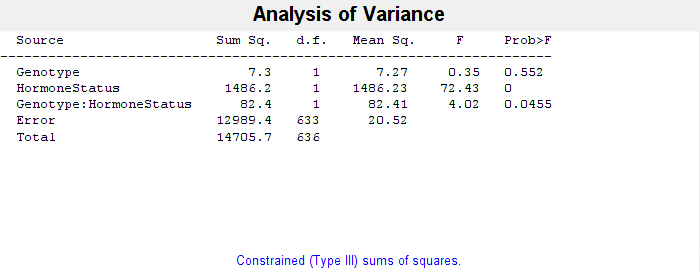

[p_FR, tbl_FR, stats_FR] = anovan(cleanedAallBLAves.spikePtime, ...
    {cleanedAallBLAves.Genotype, cleanedAallBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});

disp(tbl_FR);

    {'Source'                }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Genotype'              }    {[    7.2669]}    {[   1]}    {[        0]}    {[    7.2669]}    {[  0.3541]}    {[    0.5520]}
    {'HormoneStatus'         }    {[1.4862e+03]}    {[   1]}    {[        0]}    {[1.4862e+03]}    {[ 72.4272]}    {[1.2552e-16]}
    {'Genotype:HormoneStatus'}    {[   82.4068]}    {[   1]}    {[        0]}    {[   82.4068]}    {[  4.0158]}    {[    0.0455]}
    {'Error'                 }    {[1.2989e+04]}    {[ 633]}    {[        0]}    {[   20.5204]}    {0×0 double}    {0×0 double  }
    {'Total'                 }    {[1.4706e+04]}    {[ 636]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



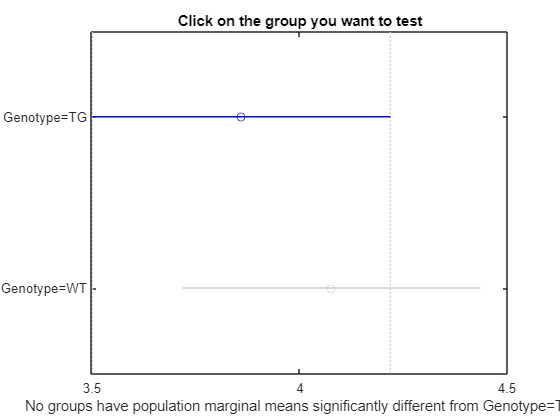


% Tukey Post-hoc Tests for Firing Rate
multcompare(stats_FR, 'Dimension', 1); % Genotype

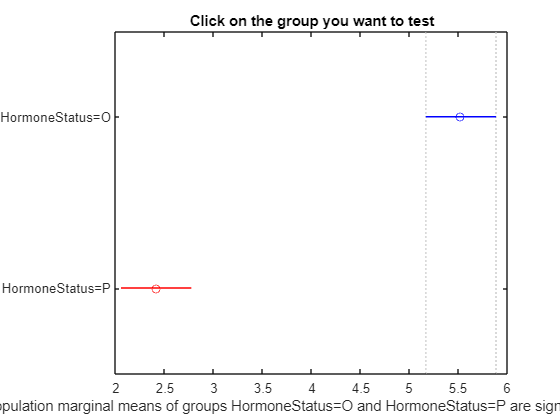

multcompare(stats_FR, 'Dimension', 2); % Hormone Status

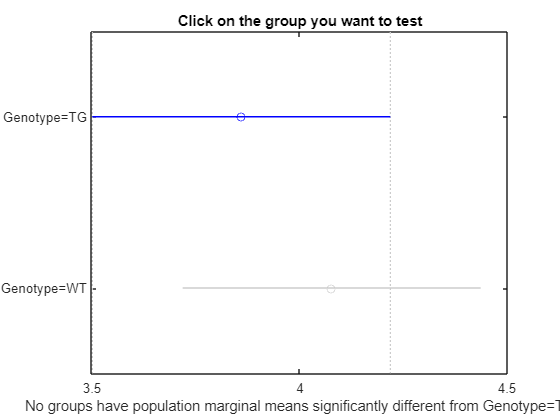

[c_FR_geno,~,~,groupNames_FR_geno] = multcompare(stats_FR, 'Dimension', 1); % Genotype

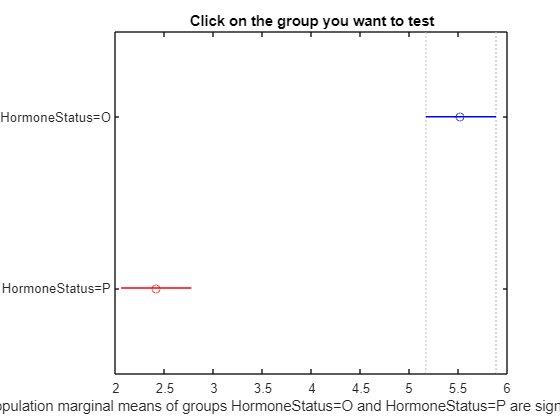

[c_FR_hormone,~,~,groupNames_FR_hormone] = multcompare(stats_FR, 'Dimension', 2); % Hormone Status


%% Step 3: Two-Way ANOVA for ISI
disp('ANOVA for ISI');

ANOVA for ISI


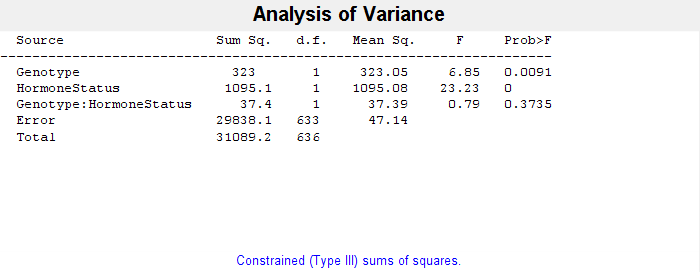

[p_ISI, tbl_ISI, stats_ISI] = anovan(cleanedAallBLAves.ISI, ...
    {cleanedAallBLAves.Genotype, cleanedAallBLAves.HormoneStatus}, ...
    'model', 'interaction', ...
    'varnames', {'Genotype', 'HormoneStatus'});

disp(tbl_ISI);

    {'Source'                }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Genotype'              }    {[  323.0488]}    {[   1]}    {[        0]}    {[  323.0488]}    {[  6.8533]}    {[    0.0091]}
    {'HormoneStatus'         }    {[1.0951e+03]}    {[   1]}    {[        0]}    {[1.0951e+03]}    {[ 23.2315]}    {[1.8001e-06]}
    {'Genotype:HormoneStatus'}    {[   37.3888]}    {[   1]}    {[        0]}    {[   37.3888]}    {[  0.7932]}    {[    0.3735]}
    {'Error'                 }    {[2.9838e+04]}    {[ 633]}    {[        0]}    {[   47.1376]}    {0×0 double}    {0×0 double  }
    {'Total'                 }    {[3.1089e+04]}    {[ 636]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



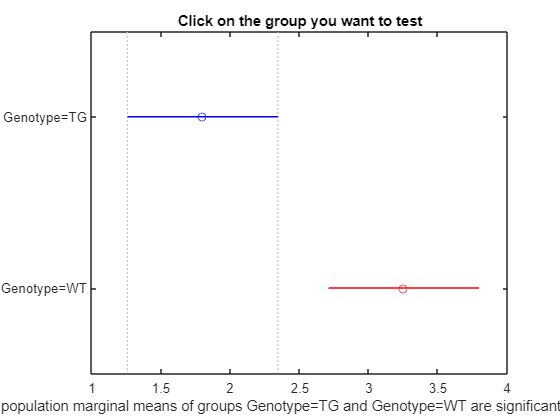


% Tukey Post-hoc Tests for ISI
multcompare(stats_ISI, 'Dimension', 1); % Genotype

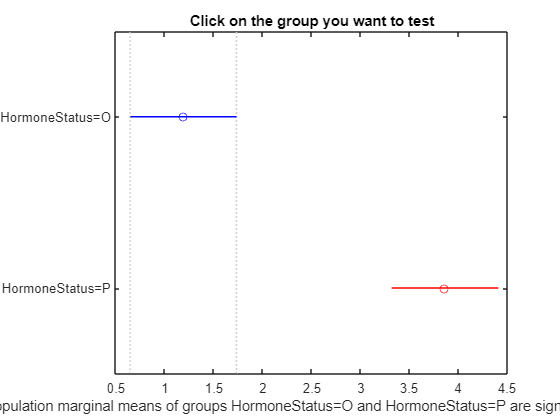

multcompare(stats_ISI, 'Dimension', 2); % Hormone Status

[c_ISI_geno,~,~,groupNames_ISI_geno] = multcompare(stats_ISI, 'Dimension', 1); % Genotype

[c_ISI_hormone,~,~,groupNames_ISI_hormone] = multcompare(stats_ISI, 'Dimension', 2); % Hormone Status

%% Step 1: Ensure Correct Data Types and Extract Factors
% Convert group to string format if it's categorical
cleanedAallBLAves.group = string(cleanedAallBLAves.group);

% Extract genotype (WT/TG) and hormone status (P/O)
cleanedAallBLAves.Genotype = categorical(extractBefore(cleanedAallBLAves.group, 3)); % First 2 characters
cleanedAallBLAves.HormoneStatus = categorical(extractAfter(cleanedAallBLAves.group, 2)); % Last character

% Create a combined categorical variable for Genotype & Hormone Status
cleanedAallBLAves.GroupID = categorical(cleanedAallBLAves.group);

% Reorder categories to make 'WT-P' the first group
cleanedAallBLAves.GroupID = reordercats(cleanedAallBLAves.GroupID, {'WTP', 'WTO', 'TGP', 'TGO'});

%% Step 2: Display Group Averages for Firing Rate
disp('Group Averages for Firing Rate:');

Group Averages for Firing Rate:


groupStats_FR = grpstats(cleanedAallBLAves, {'GroupID'}, {'mean', 'sem'}, 'DataVars', 'spikePtime');
disp(groupStats_FR);

           GroupID    GroupCount    mean_spikePtime    sem_spikePtime
           _______    __________    _______________    ______________

    WTP      WTP         116            2.8864            0.37941    
    WTO      WTO         185             5.269            0.44349    
    TGP      TGP         190            1.9346            0.13383    
    TGO      TGO         146            5.7849             0.4198    




%% Two-Way ANOVA for Firing Rate
disp('ANOVA for Firing Rate');

ANOVA for Firing Rate


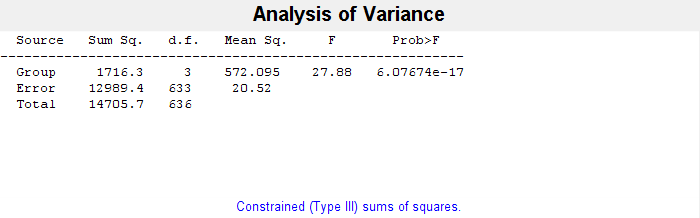

[p_FR, tbl_FR, stats_FR] = anovan(cleanedAallBLAves.spikePtime, ...
    {cleanedAallBLAves.GroupID}, ...
    'model', 'linear', ...
    'varnames', {'Group'});

disp(tbl_FR);

    {'Source'}    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'Group' }    {[1.7163e+03]}    {[   3]}    {[        0]}    {[572.0947]}    {[ 27.8793]}    {[6.0767e-17]}
    {'Error' }    {[1.2989e+04]}    {[ 633]}    {[        0]}    {[ 20.5204]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[1.4706e+04]}    {[ 636]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }




%% Tukey Post-hoc Tests for Firing Rate
disp('Tukey Post-hoc Test for Firing Rate');

Tukey Post-hoc Test for Firing Rate


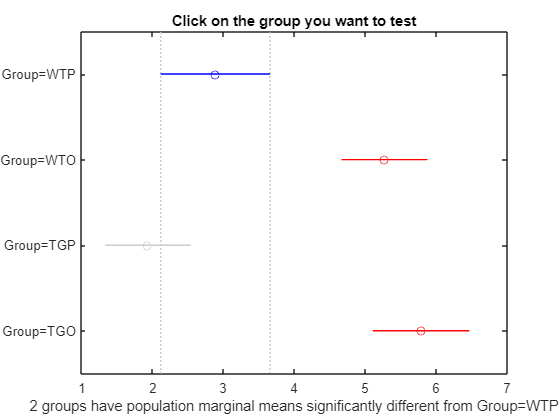

[c_FR_full,~,~,groupNames_FR_full] = multcompare(stats_FR, 'Dimension', 1);

disp(array2table(c_FR_full, 'VariableNames', {'Group1', 'Group2', 'LowerCI', 'MeanDiff', 'UpperCI', 'pValue'}));

    Group1    Group2    LowerCI     MeanDiff    UpperCI      pValue  
    ______    ______    ________    ________    _______    __________

      1         2        -3.7608     -2.3826    -1.0043    5.2903e-05
      1         3       -0.41951     0.95174      2.323       0.28145
      1         4         -4.346     -2.8985     -1.451    1.6019e-06
      2         3         2.1323      3.3343     4.5364    5.4697e-12
      2         4        -1.8042    -0.51591    0.77238       0.73254
      3         4         -5.131     -3.8502    -2.5694    4.9741e-14




%% Step 3: Display Group Averages for ISI
disp('Group Averages for ISI:');

Group Averages for ISI:


groupStats_ISI = grpstats(cleanedAallBLAves, {'GroupID'}, {'mean', 'sem'}, 'DataVars', 'ISI');
disp(groupStats_ISI);

           GroupID    GroupCount    mean_ISI    sem_ISI
           _______    __________    ________    _______

    WTP      WTP         116         4.8371      1.0478
    WTO      WTO         185         1.6678     0.43106
    TGP      TGP         190         2.8899      0.4907
    TGO      TGO         146        0.70915     0.10232




%% Two-Way ANOVA for ISI
disp('ANOVA for ISI');

ANOVA for ISI


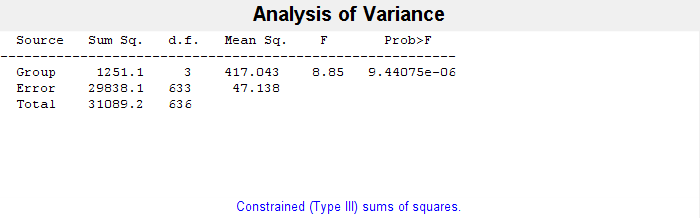

[p_ISI, tbl_ISI, stats_ISI] = anovan(cleanedAallBLAves.ISI, ...
    {cleanedAallBLAves.GroupID}, ...
    'model', 'linear', ...
    'varnames', {'Group'});

disp(tbl_ISI);

    {'Source'}    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'Group' }    {[1.2511e+03]}    {[   3]}    {[        0]}    {[417.0431]}    {[  8.8474]}    {[9.4407e-06]}
    {'Error' }    {[2.9838e+04]}    {[ 633]}    {[        0]}    {[ 47.1376]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[3.1089e+04]}    {[ 636]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }




%% Tukey Post-hoc Tests for ISI
disp('Tukey Post-hoc Test for ISI');

Tukey Post-hoc Test for ISI


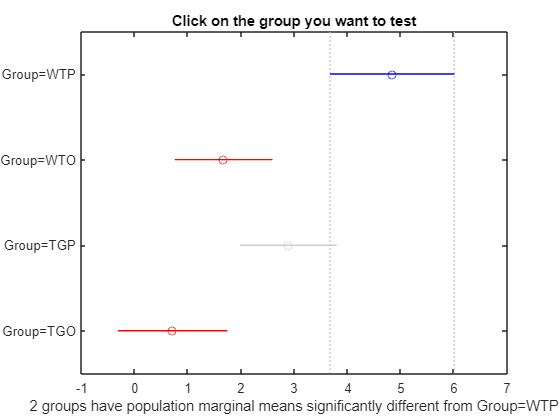

[c_ISI_full,~,~,groupNames_ISI_full] = multcompare(stats_ISI, 'Dimension', 1);

disp(array2table(c_ISI_full, 'VariableNames', {'Group1', 'Group2', 'LowerCI', 'MeanDiff', 'UpperCI', 'pValue'}));

    Group1    Group2    LowerCI     MeanDiff    UpperCI      pValue  
    ______    ______    ________    ________    _______    __________

      1         2         1.0804     3.1693     5.2583     0.00056223
      1         3       -0.13108     1.9472     4.0255       0.075734
      1         4         1.9342      4.128     6.3218     7.9641e-06
      2         3        -3.0439    -1.2221     0.5997        0.31141
      2         4       -0.99392    0.95864     2.9112        0.58768
      3         4        0.23957     2.1808      4.122        0.02037



# Paired Points across epoch

Paired Point graphs

% Define groups and epochs 
groups = {'WTP', 'TGP', 'WTO', 'TGO'};
epochs = {'BL', 'FS', 'Rest'}; % Epoch labels
numEpochs = numel(epochs);

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Define datasets for each epoch
datasets = {'cleanedAallBLAves', 'cleanedAallFSAves', 'cleanedAallRestAves'};
columnName = 'spikePtime'; % The single variable of interest

% Initialize matrices for means and SEMs
meanAverages = nan(length(groups), numEpochs);
meanSEMs = nan(length(groups), numEpochs);

% Extract data for each group and epoch
for e = 1:numEpochs
    dataTable = eval(datasets{e}); % Load corresponding dataset
    dataTable.group = categorical(dataTable.group, groups, 'Ordinal', true);

    for g = 1:length(groups)
        groupData = dataTable.(columnName)(dataTable.group == groups{g});
        groupData = groupData(~isnan(groupData)); % Remove NaNs

        if ~isempty(groupData)
            meanAverages(g, e) = mean(groupData);
            meanSEMs(g, e) = std(groupData) / sqrt(numel(groupData));
        end
    end
end

% ==== Plot Paired Mean Points with Lines ====
figure;
hold on;

% Create an empty array to store scatter handles for legend
legendHandles = gobjects(1, length(groups));

for g = 1:length(groups)
    % Scatter plot of means (these will be shown in legend)
    scatterHandle = scatter(1:numEpochs, meanAverages(g, :), 100, groupColors(g, :), 'filled');
    
    % Store the first scatter point for legend reference
    legendHandles(g) = scatterHandle;
    
    % Connecting paired points for each group (not in legend)
    lineHandle = plot(1:numEpochs, meanAverages(g, :), '-o', 'LineWidth', 1.5, ...
        'Color', groupColors(g, :));
    set(get(get(lineHandle, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');

    % Error bars for means
    e = errorbar(1:numEpochs, meanAverages(g, :), meanSEMs(g, :), 'LineStyle', 'none', ...
        'Color', groupColors(g, :), 'LineWidth', 1.2);
    set(get(get(e, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
end

% Format plot
xlim([0.5, numEpochs + 0.5]);
xticks(1:numEpochs);
xticklabels(epochs);
ylabel('Mean Firing Rate (Hz)', 'FontSize', 14);
xlabel('Epoch', 'FontSize', 14);

% Create legend with only the scatter points
legend(legendHandles, groups, 'Location', 'best');

title('Firing Rate Across Epochs');
set(gca, 'FontSize', 12, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
set(gcf, 'Color', 'w');
grid on;
hold off;


# % change from BL to FS

% Define groups and epochs 
groups = {'WTP', 'TGP', 'WTO', 'TGO'}; % Explicit order
epochs = {'BL', 'FS', 'Rest'}; % Epoch labels
numEpochs = numel(epochs);

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

%% --- Load the Datasets ---
BLdata   = cleanedAallBLAves;   % Baseline data
FSdata   = cleanedAallFSAves;   % Footshock data
Restdata = cleanedAallRestAves; % Rest data

%% --- Identify Units Present in Each Epoch ---
BLUnits   = unique(BLdata.unitID);
FSUnits   = unique(FSdata.unitID);
RestUnits = unique(Restdata.unitID);

% Find common unit IDs across all three epochs
commonUnits = intersect(intersect(BLUnits, FSUnits), RestUnits);

% Find units missing from one or more epochs
allUnits = union(BLUnits, union(FSUnits, RestUnits));
missingUnits = setdiff(allUnits, commonUnits);

if ~isempty(missingUnits)
    fprintf('Units missing in one or more epochs:\n');
    disp(missingUnits);
else
    fprintf('All units appear in all three epochs.\n');
end

%% --- Extract and Align Firing Rate Data for Common Units ---
% Define groups (explicit order) and epochs for later plotting
groups = {'WTP', 'TGP', 'WTO', 'TGO'};
epochs = {'BL', 'FS', 'Rest'}; % Epoch labels

% Initialize arrays for firing rates and group labels for the common units
nUnits = length(commonUnits);
BLFR   = nan(nUnits, 1);
FSFR   = nan(nUnits, 1);
RestFR = nan(nUnits, 1);
unitGroups = strings(nUnits, 1);

for i = 1:nUnits
    unitID = commonUnits(i);
    
    % Extract firing rates for this unit from each dataset
    % (Assuming each unit appears only once per table)
    BLFR(i)   = BLdata.spikePtime(BLdata.unitID == unitID);
    FSFR(i)   = FSdata.spikePtime(FSdata.unitID == unitID);
    RestFR(i) = Restdata.spikePtime(Restdata.unitID == unitID);
    
    % Assign group label (assuming BLdata contains correct group labels)
    unitGroups(i) = string(BLdata.group(BLdata.unitID == unitID));
end

% Convert unitGroups to a categorical array with explicit group order
unitGroups = categorical(unitGroups, groups, 'Ordinal', true);

%% --- Calculate % Change in Firing Rate ---
percentChange_FS   = ((FSFR - BLFR) ./ BLFR) * 100;   % Change from BL to FS
percentChange_Rest = ((RestFR - BLFR) ./ BLFR) * 100;  % Change from BL to Rest

%% --- Plotting Parameters ---
% Set jitter amount for scatter plots
jitterAmount = 0.2; 

% Initialize arrays for summary counts
numAbove_FS   = zeros(length(groups), 1);
numBelow_FS   = zeros(length(groups), 1);
numAbove_Rest = zeros(length(groups), 1);
numBelow_Rest = zeros(length(groups), 1);

%% --- Plot 1: % Change from BL to FS ---
figure;
hold on;
for g = 1:length(groups)
    % Identify indices for the current group
    groupIdx = (unitGroups == groups{g});
    
    % Generate random jitter for x-coordinates
    jitteredX = g + (rand(sum(groupIdx), 1) - 0.5) * jitterAmount;
    
    % Scatter plot for current group
scatter(jitteredX, percentChange_FS(groupIdx), 100, ...
    'MarkerFaceColor', groupColors(g, :), 'MarkerEdgeColor', 'k', ...
    'Marker', 'o', 'LineWidth', 1.2, 'DisplayName', groups{g});

    
    % Count units above and below zero
    numAboveZero = sum(percentChange_FS(groupIdx) > 0);
    numBelowZero = sum(percentChange_FS(groupIdx) < 0);
    
    % Save counts for summary table
    numAbove_FS(g) = numAboveZero;
    numBelow_FS(g) = numBelowZero;
    
    
end

% Add a horizontal dashed line at y = 0
yline(0, '--k', 'LineWidth', 1);

% Customize the BL to FS plot
ylim([-100, 100]);
xlim([0.5, length(groups) + 0.5]);
xticks(1:length(groups));
xticklabels(groups);
ylabel('Change in Firing Rate during Foot Shock (%)', 'FontSize', 24);
xlabel('Groups', 'FontSize', 24);
set(gca, 'FontSize', 12, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
set(gcf, 'Color', 'w');
grid on;
box off;
hold off;



%% --- Summary Table ---
summaryTable = table(groups', numAbove_FS, numBelow_FS, numAbove_Rest, numBelow_Rest, ...
    'VariableNames', {'Group', 'AboveZero_FS', 'BelowZero_FS', 'AboveZero_Rest', 'BelowZero_Rest'});
disp('Summary Table: Number of Units Above and Below Zero in Each Group');
disp(summaryTable);


Chi Squared for BL to FS numbers

% Data: Increase and Decrease percentages
data_FS = [34.3, 65.7;  % WTP
           34.8, 65.2; % TGP
           75.6, 24.4; % WTO
           27.9, 72.1]; % TGO


% Perform Chi-Square Test for BL to FS
[p_FS, chi2_FS, stats_FS] = chi2cont(data_FS);



% Display Results
fprintf('Chi-Square Test for BL to FS: χ² = %.2f, p = %.4f\n', chi2_FS, p_FS);

% Groups
groups = {'WTP', 'TGP', 'WTO', 'TGO'};
numGroups = length(groups);

% Perform Overall Chi-Square Test for All Groups
[p_FS, chi2_FS, stats_FS] = chi2cont(data_FS);
fprintf('Chi-Square Test for All Groups (BL to FS): χ² = %.2f, p = %.4f\n', chi2_FS, p_FS);

% Perform Pairwise Comparisons
for i = 1:numGroups-1
    for j = i+1:numGroups
        % Extract subset for pairwise chi-square test
        pairwise_data = data_FS([i, j], :);
        
        % Perform chi-square test
        [p_pair, chi2_pair, stats_pair] = chi2cont(pairwise_data);
        
        % Display results
        fprintf('Pairwise Chi-Square Test (%s vs. %s): χ² = %.2f, p = %.4f\n', ...
            groups{i}, groups{j}, chi2_pair, p_pair);
    end
end



# BL to rest paired points

% Define groups and epochs
groups = {'WTP', 'TGP', 'WTO', 'TGO'}; % Explicit order
epochs = {'Baseline', 'Rest'}; % Updated to compare BL to Rest

% Define group colors
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

%% --- Load the Datasets ---
BLdata   = cleanedAallBLAves;   % Baseline data
Restdata = cleanedAallRestAves; % Rest data

%% --- Identify Units Present in Both Epochs ---
BLUnits   = unique(BLdata.unitID);
RestUnits = unique(Restdata.unitID);

% Find common unit IDs across both epochs
commonUnits = intersect(BLUnits, RestUnits);

% Initialize arrays for firing rates and group labels
nUnits = length(commonUnits);
BLFR   = nan(nUnits, 1);
RestFR = nan(nUnits, 1);
unitGroups = strings(nUnits, 1);

for i = 1:nUnits
    unitID = commonUnits(i);
    
    % Extract firing rates for each unit in both epochs
    BLFR(i)   = BLdata.spikePtime(BLdata.unitID == unitID);
    RestFR(i) = Restdata.spikePtime(Restdata.unitID == unitID);
    
    % Assign group label (assuming BLdata contains correct group labels)
    unitGroups(i) = string(BLdata.group(BLdata.unitID == unitID));
end

% Convert unitGroups to a categorical array with explicit group order
unitGroups = categorical(unitGroups, groups, 'Ordinal', true);

% Identify increasing and decreasing firing rate units
increasingIdx = RestFR > BLFR;
decreasingIdx = RestFR < BLFR;

%% --- Create Figure with Subplots for Increasing and Decreasing Firing Rate ---
figure;

jitterAmount = 0.1; % Small horizontal jitter

for g = 1:length(groups)
    % Select units in this group
    groupIdx_inc = (unitGroups == groups{g}) & increasingIdx;
    groupIdx_dec = (unitGroups == groups{g}) & decreasingIdx;
    
    % Extract data for increasing units
    BLFR_inc = BLFR(groupIdx_inc);
    RestFR_inc = RestFR(groupIdx_inc);
    
    % Extract data for decreasing units
    BLFR_dec = BLFR(groupIdx_dec);
    RestFR_dec = RestFR(groupIdx_dec);
    
    % X-positions with jitter
    xBL_inc = ones(sum(groupIdx_inc), 1) + (rand(sum(groupIdx_inc), 1) - 0.5) * jitterAmount;
    xRest_inc = xBL_inc + 1;
    
    xBL_dec = ones(sum(groupIdx_dec), 1) + (rand(sum(groupIdx_dec), 1) - 0.5) * jitterAmount;
    xRest_dec = xBL_dec + 1;
    
    % --- Increasing Firing Rate Subplot ---
    subplot(2, length(groups), g);
    hold on;
    %title([groups{g} ' - Increasing'], 'FontSize', 12);
    
    % Plot paired lines
    for i = 1:length(BLFR_inc)
        plot([xBL_inc(i), xRest_inc(i)], [BLFR_inc(i), RestFR_inc(i)], '-', ...
            'Color', groupColors(g, :), 'LineWidth', 1.5);
    end

    % Scatter plot
    scatter(xBL_inc, BLFR_inc, 100, groupColors(g, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'MarkerFaceAlpha', 0.7);
    scatter(xRest_inc, RestFR_inc, 100, groupColors(g, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'MarkerFaceAlpha', 0.7);
    
    xlim([0.5, 2.5]);
    xticks([1, 2]);
    xticklabels({'Baseline', 'Post Shock Rest'});
    ylabel('Firing Rate (Hz)');
    set(gca, 'FontSize', 14, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
    grid on;
    box off;
    hold off;

    % --- Decreasing Firing Rate Subplot ---
    subplot(2, length(groups), g + length(groups));
    hold on;
    %title([groups{g} ' - Decreasing'], 'FontSize', 12);
    
    % Plot paired lines
    for i = 1:length(BLFR_dec)
        plot([xBL_dec(i), xRest_dec(i)], [BLFR_dec(i), RestFR_dec(i)], '-', ...
            'Color', groupColors(g, :), 'LineWidth', 1.5);
    end

    % Scatter plot
    scatter(xBL_dec, BLFR_dec, 100, groupColors(g, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'MarkerFaceAlpha', 0.7);
    scatter(xRest_dec, RestFR_dec, 100, groupColors(g, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'MarkerFaceAlpha', 0.7);
    
    xlim([0.5, 2.5]);
    xticks([1, 2]);
    xticklabels({'Baseline', 'Post Shock Rest'});
    ylabel('Firing Rate (Hz)');
    set(gca, 'FontSize', 14, 'Color', 'w', 'XColor', 'k', 'YColor', 'k');
    grid on;
    box off;
    hold off;
end


% Set uniform y-axis limits for all subplots
globalMinFR = min([BLFR; RestFR]); 
globalMaxFR = max([BLFR; RestFR]); 
yLimits = [globalMinFR - 1, globalMaxFR + 1];

for g = 1:(2 * length(groups))
    subplot(2, length(groups), g);
    ylim(yLimits); % Apply uniform y-axis limits
end

%sgtitle('Firing Rate Changes: Baseline to Rest', 'FontSize', 16);

%% --- Summary Statistics ---
summaryIncreasing = table(groups', avgBL_Increasing, stdBL_Increasing, avgRest_Increasing, stdRest_Increasing, ...
    change_Increasing, foldChange_Increasing, ...
    'VariableNames', {'Group', 'Avg_BL', 'Std_BL', 'Avg_Rest', 'Std_Rest', 'Change', 'Fold_Change'});

summaryDecreasing = table(groups', avgBL_Decreasing, stdBL_Decreasing, avgRest_Decreasing, stdRest_Decreasing, ...
    change_Decreasing, foldChange_Decreasing, ...
    'VariableNames', {'Group', 'Avg_BL', 'Std_BL', 'Avg_Rest', 'Std_Rest', 'Change', 'Fold_Change'});

disp('Summary Statistics for Increasing Units:');
disp(summaryIncreasing);

disp('Summary Statistics for Decreasing Units:');
disp(summaryDecreasing);


#### Testing for Differences in changes

% Data: Increase and Decrease Counts
data_FS = [34.3, 65.7;  % WTP
           34.8, 65.2; % TGP
           75.6, 24.4; % WTO
           27.9, 72.1]; % TGO

data_Rest = [57, 51;  % WTP
             75, 113; % TGP
             85 83;  % WTO
             58, 85]; % TGO

% Perform Chi-Square Test for BL to FS
[p_FS, chi2_FS, stats_FS] = chi2cont(data_FS);

% Perform Chi-Square Test for BL to Rest
[p_Rest, chi2_Rest, stats_Rest] = chi2cont(data_Rest);

% Display Results
fprintf('Chi-Square Test for BL to FS: χ² = %.2f, p = %.4f\n', chi2_FS, p_FS);
fprintf('Chi-Square Test for BL to Rest: χ² = %.2f, p = %.4f\n', chi2_Rest, p_Rest);


# Cleaning Outliers out of bursts

cleanedAallBursts = allBursts(~ismember(allBursts.unitID, outlierUnits), :);
cleanedBlBursts = BlBursts(~ismember(BlBursts.unitID, outlierUnits), :);
cleanedFsBursts = FsBursts(~ismember(FsBursts.unitID, outlierUnits), :);
cleanedrestBursts = restBursts(~ismember(restBursts.unitID, outlierUnits), :);

# Burst Raster 

result = cleanedAallBursts;
figure;
hold on;

% Define colors and colormap
cmap = jet; % Default colormap for MATLAB
darkRed = [0.5 0 0];
color_limit = 40; % Cap the color scale

% Convert timestamps to minutes
result.AdjustedTime = result.StartTime / 60; 

% ✅ Identify and shift timestamps after 889s to remove the gap
gapStart = 14.82; % 889s in minutes
gapEnd = 15; % 900s in minutes
gapDuration = gapEnd - gapStart; % Size of the missing time (0.18 min)

% Find indices where timestamps occur after the gap
postGapIndices = result.AdjustedTime > gapEnd;

% Shift timestamps after the gap **downward** by `gapDuration`
result.AdjustedTime(postGapIndices) = result.AdjustedTime(postGapIndices) - gapDuration;

% Find unique units for each lightCycle
WTP_units = unique(result.unitID(result.group == 'WTP'));
TGP_units = unique(result.unitID(result.group == 'TGP'));
WTO_units = unique(result.unitID(result.group == 'WTO'));
TGO_units = unique(result.unitID(result.group == 'TGO'));

% Find unique units for each lightCycle and compute their average firing rates
groupNames = {'WTP', 'TGP', 'WTO', 'TGO'}; % Maintain order of groups
sortedUnits = []; % Initialize sorted unit list

for g = 1:length(groupNames)
    group = groupNames{g};
    unitsInGroup = unique(result.unitID(result.group == group));
    
    % Compute the average firing rate for each unit
    avgFiringRates = arrayfun(@(u) mean(result.FiringRate(result.unitID == u)), unitsInGroup);

    % Sort units within the group based on average firing rate (descending)
    [~, sortIdx] = sort(avgFiringRates, 'descend');
    sortedUnits = [sortedUnits; unitsInGroup(sortIdx)]; % Append sorted units
end

% Use sorted units in plotting
combinedUnits = sortedUnits;
countUnits = length(combinedUnits) + 1;

% Chunk size for plotting
chunkSize = 10;

% Loop through combined units in chunks
for chunkStart = 1:chunkSize:length(combinedUnits)
    chunkEnd = min(chunkStart + chunkSize - 1, length(combinedUnits));
    currentChunk = combinedUnits(chunkStart:chunkEnd);

    % Loop through the current chunk of units and plot
    for i = 1:length(currentChunk)
        unitRows = result.unitID == currentChunk(i);
        unitTimestamp = result.AdjustedTime(unitRows); % ✅ Use adjusted timestamps
        firingRate = result.FiringRate(unitRows);

        % Cap the firing rate at 40 for coloring
        cappedFiringRate = min(firingRate, color_limit);

        % Normalize firing rate for colormap
        normalizedFiringRate = cappedFiringRate / color_limit;

        % Get colormap color based on firing rate
        colorValues = interp1(linspace(0, 1, size(cmap, 1)), cmap, normalizedFiringRate);

        % Assign colors, vectorized instead of loop
        colors = repmat(darkRed, length(firingRate), 1); % Pre-assign dark red
        lowFiringRateIdx = firingRate <= 40;
        colors(lowFiringRateIdx, :) = colorValues(lowFiringRateIdx, :); % Assign colormap for firing rate <= 40

        % Plot all scatter points in one go, without looping
        scatter(unitTimestamp, repmat(i + chunkStart - 1, size(unitTimestamp)), 200, colors, 'Marker', '|', 'SizeData', 20);
    end

    % Plot vertical lines after scatter plots for each chunk
    line([10, 10], [chunkStart, chunkEnd], 'Color', 'k', 'LineWidth', 1.5); 
    line([15 - gapDuration, 15 - gapDuration], [chunkStart, chunkEnd], 'Color', 'k', 'LineWidth', 1.5); % ✅ Adjusted 15-min marker
    line([25 - gapDuration, 25 - gapDuration], [chunkStart, chunkEnd], 'Color', 'k', 'LineWidth', 1.5); % ✅ Adjusted 25-min marker
end

% Set x-axis limits
xMin = 0;
xMax = 20 - gapDuration; % ✅ Adjusted x-axis range
xlim([xMin, xMax]);

xlabel('Time (min)');
ylabel('Unit');
set(gca, 'YDir', 'reverse');

% Set the y-axis limit to match the actual number of units plotted
ylim([1, countUnits - 1]); % Adjust countUnits - 1 to avoid extra space

% ✅ Add horizontal lines only between groups

% Extract corresponding group labels for combinedUnits
sortedGroups = arrayfun(@(x) result.group(find(result.unitID == x, 1, 'first')), combinedUnits, 'UniformOutput', false);

% Ensure sortedGroups is a cell array of character vectors
sortedGroups = cellfun(@char, sortedGroups, 'UniformOutput', false);

% Find unique group transitions
[~, ~, groupIdx] = unique(sortedGroups, 'stable'); % Group index for each row
groupBoundaries = find(diff(groupIdx) ~= 0); % Find where group changes

% Add horizontal lines only at group boundaries
for i = 1:numel(groupBoundaries)
    yPosition = groupBoundaries(i) + 0.5; % Position between groups
    line([xMin, xMax], [yPosition, yPosition], 'Color', 'k', 'LineWidth', 2); % Black lines
end

hold off;

% ✅ Create a color bar for the firing rate capped at 40
colormap(cmap);
c = colorbar;
caxis([0 color_limit]);
ylabel(c, 'Firing Rate (Hz)');



# Counting Bursts 

% Define the correct order of groups
groupOrder = {'WTP', 'TGP', 'WTO', 'TGO'};
numGroups = length(groupOrder);

% Define colors for each group
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Define epochs and corresponding tables
epochs = {'Baseline', 'Foot Shock', 'Rest'};
tables = {cleanedBlBursts, cleanedFsBursts, cleanedrestBursts};
numEpochs = length(epochs);

% Initialize storage for mean and standard error per group and epoch
meanBursts = zeros(numGroups, numEpochs);
SEBursts = zeros(numGroups, numEpochs);

% Store all individual data points for scatter plotting
allUnitData = cell(numGroups, numEpochs);

% Loop through epochs and calculate burst counts per unit
for i = 1:numEpochs
    currTable = tables{i};  % Get current epoch's table

    for j = 1:numGroups
        groupName = groupOrder{j};

        % Get subset of data for this group
        groupData = currTable(strcmp(currTable.group, groupName), :);
        
        % Count bursts per unit
        [unitIDs, ~, idx] = unique(groupData.unitID);
        burstCounts = accumarray(idx, 1); % Count occurrences per unit

        % Store raw data points
        allUnitData{j, i} = burstCounts;

        % Compute mean and standard error
        meanBursts(j, i) = mean(burstCounts);
        SEBursts(j, i) = std(burstCounts) / sqrt(length(unitIDs));
    end
end

% Create bar plot
figure;
barWidth = 0.8; % Adjust bar width
barHandle = bar(meanBursts', 'grouped', 'BarWidth', barWidth);

% Set colors for bars
for j = 1:numGroups
    barHandle(j).FaceColor = groupColors(j, :);
end
hold on;

% Get x positions of bars for each group and epoch
barPositions = zeros(numGroups, numEpochs);
for i = 1:numEpochs
    for j = 1:numGroups
        barPositions(j, i) = barHandle(j).XEndPoints(i);
    end
end

% Overlay individual data points correctly
for i = 1:numEpochs
    for j = 1:numGroups
        % Get burst counts for individual units
        data = allUnitData{j, i};

        % Get the correct x position for the group in the epoch
        xPos = barPositions(j, i);
        
        % Add slight jitter to spread points
        jitterAmount = 0.05; 
        xJitter = xPos + (rand(size(data)) - 0.5) * jitterAmount;
        
        % Plot individual unit data points
        plot(xJitter, data, 'k.', 'MarkerSize', 8);
    end
end

% Add error bars
for i = 1:numEpochs
    errorbar(barPositions(:, i), meanBursts(:, i), SEBursts(:, i), 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
end

hold off;

% Customize axes and labels
xticks(1:numEpochs);
xticklabels(epochs);
xlabel('Epoch');
ylabel('Number of Bursts per Unit');
legend(groupOrder, 'Location', 'northeastoutside');
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
grid on;
box on;


# two way ANOVA  burst count

%% Step 1: Prepare Data for Repeated-Measures ANOVA (Wide Format)

% Define the correct order of groups
groupOrder = {'WTP', 'TGP', 'WTO', 'TGO'};
numGroups = length(groupOrder);
epochs = {'BL', 'FS', 'Rest'};
numEpochs = length(epochs);

% Create an empty cell array to store data for all units
unitDataList = {};

% Unique unit counter
unitIdx = 1;

for j = 1:numGroups
    groupName = groupOrder{j};  % Group label
    
    % Extract burst count data for each epoch
    BL_values = allUnitData{j, 1}; % BL epoch burst counts
    FS_values = allUnitData{j, 2}; % FS epoch burst counts
    Rest_values = allUnitData{j, 3}; % Rest epoch burst counts
    
    % Find the maximum number of units in this group across all epochs
    maxUnits = max([length(BL_values), length(FS_values), length(Rest_values)]);

    % Pad missing values with NaN (to indicate no bursts in that epoch)
    BL_values = padarray(BL_values, [maxUnits - length(BL_values), 0], NaN, 'post');
    FS_values = padarray(FS_values, [maxUnits - length(FS_values), 0], NaN, 'post');
    Rest_values = padarray(Rest_values, [maxUnits - length(Rest_values), 0], NaN, 'post');

    % Store each unit's data in the list
    for k = 1:maxUnits
        unitDataList{end+1, 1} = categorical({groupName}); % Group
        unitDataList{end, 2} = unitIdx;  % Unique Unit ID
        unitDataList{end, 3} = BL_values(k); % BL epoch burst count
        unitDataList{end, 4} = FS_values(k); % FS epoch burst count
        unitDataList{end, 5} = Rest_values(k); % Rest epoch burst count
        unitIdx = unitIdx + 1;
    end
end

% Convert cell array to table
unitData = cell2table(unitDataList, 'VariableNames', {'Group', 'UnitID', 'BL', 'FS', 'Rest'});







%% Step 2: Define Repeated-Measures Model and Run ANOVA

% Define the within-subject factor (Epoch)
withinFactors = table({'BL'; 'FS'; 'Rest'}, 'VariableNames', {'Epoch'});

% Fit repeated-measures model (BL, FS, Rest as within-subject measures)
rm = fitrm(unitData, 'BL-Rest ~ Group', 'WithinDesign', withinFactors);

% Run repeated-measures ANOVA
ranovaResults = ranova(rm);
disp('Repeated-Measures ANOVA Results:');
disp(ranovaResults);

%% Step 3: Post-Hoc Comparisons

% Pairwise comparisons between groups within each epoch
groupPostHoc = multcompare(rm, 'Group', 'ComparisonType', 'bonferroni');
disp('Post-Hoc Comparisons Between Groups:');
disp(groupPostHoc);

% Pairwise comparisons between epochs within each group
epochPostHoc = multcompare(rm, 'Epoch', 'ComparisonType', 'bonferroni');
disp('Post-Hoc Comparisons Between Epochs:');
disp(epochPostHoc);


Burst COunt averages per group

% Count bursts per unit per group for each epoch
BL_counts = varfun(@numel, cleanedBlBursts, 'GroupingVariables', {'group', 'unitID'}, 'InputVariables', 'unitID');
FS_counts = varfun(@numel, cleanedFsBursts, 'GroupingVariables', {'group', 'unitID'}, 'InputVariables', 'unitID');
Rest_counts = varfun(@numel, cleanedrestBursts, 'GroupingVariables', {'group', 'unitID'}, 'InputVariables', 'unitID');

% Compute both mean and standard deviation in a single step
BL_stats = groupsummary(BL_counts, 'group', {'mean', 'std'}, 'numel_unitID');
FS_stats = groupsummary(FS_counts, 'group', {'mean', 'std'}, 'numel_unitID');
Rest_stats = groupsummary(Rest_counts, 'group', {'mean', 'std'}, 'numel_unitID');

% Rename columns for clarity
BL_stats = renamevars(BL_stats, ["mean_numel_unitID", "std_numel_unitID"], ["BL_Mean", "BL_Std"]);
FS_stats = renamevars(FS_stats, ["mean_numel_unitID", "std_numel_unitID"], ["FS_Mean", "FS_Std"]);
Rest_stats = renamevars(Rest_stats, ["mean_numel_unitID", "std_numel_unitID"], ["Rest_Mean", "Rest_Std"]);

% Merge results into a single table
epochStats = join(join(BL_stats(:, ["group", "BL_Mean", "BL_Std"]), ...
                       FS_stats(:, ["group", "FS_Mean", "FS_Std"])), ...
                       Rest_stats(:, ["group", "Rest_Mean", "Rest_Std"]));

% Display the results
disp(epochStats);

% Combine unit-level burst counts from all epochs
anovaTable = [
    BL_counts.unitID, BL_counts.group, repmat("BL", size(BL_counts, 1), 1), BL_counts.numel_unitID;
    FS_counts.unitID, FS_counts.group, repmat("FS", size(FS_counts, 1), 1), FS_counts.numel_unitID;
    Rest_counts.unitID, Rest_counts.group, repmat("Rest", size(Rest_counts, 1), 1), Rest_counts.numel_unitID
];

% Convert to table with proper data types
anovaTable = array2table(anovaTable, 'VariableNames', {'UnitID', 'Group', 'Epoch', 'BurstCount'});

% Convert 'Group' and 'Epoch' to categorical variables
anovaTable.Group = categorical(anovaTable.Group);
anovaTable.Epoch = categorical(anovaTable.Epoch);
anovaTable.BurstCount = double(anovaTable.BurstCount); % Ensure dependent variable is numeric

% Run Two-Way ANOVA
[p, tbl, stats] = anovan(anovaTable.BurstCount, {anovaTable.Group, anovaTable.Epoch}, ...
    'model', 'interaction', ...
    'varnames', {'Group', 'Epoch'});

% Display results
disp(tbl);

% Perform post-hoc comparisons
multcompare(stats, 'Dimension', 1); % Compare Groups
multcompare(stats, 'Dimension', 2); % Compare Epochs

% Define epoch names
epochNames = {'BL', 'FS', 'Rest'};

% Loop through each epoch separately
for i = 1:length(epochNames)
    epoch = epochNames{i};
    
    % Extract burst counts only for the current epoch
    epochData = anovaTable.BurstCount(anovaTable.Epoch == epoch);
    groupLabels = anovaTable.Group(anovaTable.Epoch == epoch);
    
    % Convert group labels to categorical to avoid string issues
    groupLabels = categorical(groupLabels);

    % Run one-way ANOVA for groups within the current epoch
    [p, tbl, stats] = anova1(epochData, groupLabels, 'off');  % 'off' suppresses figure
    
    % Create a new figure for each epoch before multcompare
    figure('Name', sprintf('Post-hoc comparisons for Epoch: %s', epoch), 'NumberTitle', 'off');

    % Run Tukey’s HSD post-hoc test
    fprintf('\nPost-hoc comparisons for Epoch: %s\n', epoch);
    compResults = multcompare(stats);  % Tukey's HSD is default
end

% Define epoch names
epochNames = {'BL', 'FS', 'Rest'};
significantResults = {}; % Cell array to store results

% Loop through each epoch separately
for i = 1:length(epochNames)
    epoch = epochNames{i};
    
    % Extract burst counts only for the current epoch
    epochData = anovaTable.BurstCount(anovaTable.Epoch == epoch);
    groupLabels = anovaTable.Group(anovaTable.Epoch == epoch);
    
    % Convert group labels to categorical to avoid string issues
    groupLabels = categorical(groupLabels);

    % Run one-way ANOVA for groups within the current epoch
    [p, tbl, stats] = anova1(epochData, groupLabels, 'off');  % 'off' suppresses figure
    
    % Run Tukey’s HSD post-hoc test
    compResults = multcompare(stats);  % Tukey's HSD is default
    
    % Extract significant comparisons (p < 0.05)
    significantIdx = compResults(:,6) < 0.05; % Column 6 contains p-values
    sigComparisons = compResults(significantIdx, :);
    
    % Format results into readable structure
    for j = 1:size(sigComparisons, 1)
        group1 = string(stats.gnames(sigComparisons(j, 1))); % Group 1
        group2 = string(stats.gnames(sigComparisons(j, 2))); % Group 2
        pValue = sigComparisons(j, 6); % Extract p-value
        
        % Store in results cell
        significantResults = [significantResults; {epoch, group1, group2, pValue}];
    end
end

% Convert to table
summaryTable = cell2table(significantResults, ...
    'VariableNames', {'Epoch', 'Group1', 'Group2', 'pValue'});

% Display results
disp('Significant Differences Between Groups in Each Epoch:');
disp(summaryTable);






# Burst Rate

%% Step 1: Calculate Burst Rate (bursts/sec) for Each Unit

% Define the correct order of groups
groupOrder = {'WTP', 'TGP', 'WTO', 'TGO'};
numGroups = length(groupOrder);

% Define colors for each group
groupColors = [1 0.75 0.8;  % WTP (Light Pink)
               0.7 0.5 0.7;  % TGP (Purple)
               0.85 0.3 0.5; % WTO (Reddish Pink)
               0.5 0.1 0.4]; % TGO (Dark Purple)

% Define epochs, corresponding tables, and time duration (in seconds)
epochs = {'Baseline', 'Foot Shock', 'Rest'};
tables = {cleanedBlBursts, cleanedFsBursts, cleanedrestBursts};
epochDurations = [600, 300, 600];  % BL = 600s, FS = 300s, Rest = 600s
numEpochs = length(epochs);

% Initialize storage for mean, standard error, and standard deviation per group and epoch
meanBurstRates = zeros(numGroups, numEpochs);
SEBurstRates = zeros(numGroups, numEpochs);
stdBurstRates = zeros(numGroups, numEpochs); % Standard deviation storage

% Store all individual burst rate data points for scatter plotting
allUnitData = cell(numGroups, numEpochs);

% Loop through epochs and calculate burst rate per unit
for i = 1:numEpochs
    currTable = tables{i};  % Get current epoch's table
    epochTime = epochDurations(i);  % Get corresponding epoch duration

    for j = 1:numGroups
        groupName = groupOrder{j};

        % Get subset of data for this group
        groupData = currTable(strcmp(currTable.group, groupName), :);
        
        % Count bursts per unit
        [unitIDs, ~, idx] = unique(groupData.unitID);
        burstCounts = accumarray(idx, 1); % Count occurrences per unit

        % Compute burst rate (bursts/sec)
        burstRates = burstCounts / epochTime;

        % Store raw data points
        allUnitData{j, i} = burstRates;

        % Compute mean, standard error, and standard deviation
        meanBurstRates(j, i) = mean(burstRates, 'omitnan');
        stdBurstRates(j, i) = std(burstRates, 'omitnan'); % Standard deviation
        SEBurstRates(j, i) = stdBurstRates(j, i) / sqrt(length(unitIDs)); % Standard error

        % Print results
        fprintf('%s - %s: Mean Burst Rate = %.4f bursts/sec, Std Dev = %.4f\n', ...
            groupName, epochs{i}, meanBurstRates(j, i), stdBurstRates(j, i));
    end
end


%% Step 2: Create Bar Plot for Burst Rate

figure;
barWidth = 0.8; % Adjust bar width
barHandle = bar(meanBurstRates', 'grouped', 'BarWidth', barWidth);

% Set colors for bars
for j = 1:numGroups
    barHandle(j).FaceColor = groupColors(j, :);
end
hold on;

% Get x positions of bars for each group and epoch
barPositions = zeros(numGroups, numEpochs);
for i = 1:numEpochs
    for j = 1:numGroups
        barPositions(j, i) = barHandle(j).XEndPoints(i);
    end
end

% Overlay individual data points correctly
for i = 1:numEpochs
    for j = 1:numGroups
        % Get burst rate data for individual units
        data = allUnitData{j, i};

        % Get the correct x position for the group in the epoch
        xPos = barPositions(j, i);
        
        % Add slight jitter to spread points
        jitterAmount = 0.05; 
        xJitter = xPos + (rand(size(data)) - 0.5) * jitterAmount;
        
        % Plot individual unit data points
        plot(xJitter, data, 'k.', 'MarkerSize', 8);
    end
end

% Add error bars
for i = 1:numEpochs
    errorbar(barPositions(:, i), meanBurstRates(:, i), SEBurstRates(:, i), 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
end

hold off;

% Customize axes and labels
xticks(1:numEpochs);
xticklabels(epochs);
xlabel('Epoch');
ylabel('Burst Rate (bursts/sec)');
legend(groupOrder, 'Location', 'northeastoutside');
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
grid on;
box on;

%% Step 3: Prepare Data for Repeated-Measures ANOVA (Wide Format)

% Create an empty cell array to store data for all units
unitDataList = {};

% Unique unit counter
unitIdx = 1;

for j = 1:numGroups
    groupName = groupOrder{j};  % Group label
    
    % Extract burst rate data for each epoch
    BL_rates = allUnitData{j, 1}; % BL epoch burst rates
    FS_rates = allUnitData{j, 2}; % FS epoch burst rates
    Rest_rates = allUnitData{j, 3}; % Rest epoch burst rates
    
    % Find the maximum number of units in this group across all epochs
    maxUnits = max([length(BL_rates), length(FS_rates), length(Rest_rates)]);

    % Pad missing values with NaN (to indicate no bursts in that epoch)
    BL_rates = padarray(BL_rates, [maxUnits - length(BL_rates), 0], NaN, 'post');
    FS_rates = padarray(FS_rates, [maxUnits - length(FS_rates), 0], NaN, 'post');
    Rest_rates = padarray(Rest_rates, [maxUnits - length(Rest_rates), 0], NaN, 'post');

    % Store each unit's data in the list
    for k = 1:maxUnits
        unitDataList{end+1, 1} = categorical({groupName}); % Group
        unitDataList{end, 2} = unitIdx;  % Unique Unit ID
        unitDataList{end, 3} = BL_rates(k); % BL epoch burst rate
        unitDataList{end, 4} = FS_rates(k); % FS epoch burst rate
        unitDataList{end, 5} = Rest_rates(k); % Rest epoch burst rate
        unitIdx = unitIdx + 1;
    end
end

% Convert cell array to table
unitData = cell2table(unitDataList, 'VariableNames', {'Group', 'UnitID', 'BL', 'FS', 'Rest'});

% Display structured data
disp('Structured Data for ANOVA (Wide Format):');
disp(unitData);

%% Step 4: Define Repeated-Measures Model and Run ANOVA

% Define the within-subject factor (Epoch)
withinFactors = table({'BL'; 'FS'; 'Rest'}, 'VariableNames', {'Epoch'});

% Fit repeated-measures model (BL, FS, Rest as within-subject measures)
rm = fitrm(unitData, 'BL-Rest ~ Group', 'WithinDesign', withinFactors);

% Run repeated-measures ANOVA
ranovaResults = ranova(rm);
disp('Repeated-Measures ANOVA Results:');
disp(ranovaResults);

%% Step 5: Post-Hoc Comparisons

% Pairwise comparisons between epochs within each group
epochPostHoc = multcompare(rm, 'Epoch', 'ComparisonType', 'bonferroni');
disp('Post-Hoc Comparisons Between Epochs:');
disp(epochPostHoc);

%% Step 6: Compare Burst Rate Across Groups in Each Epoch

% Initialize a results table for ANOVA outcomes
anovaResults = table();

% Loop through each epoch and perform one-way ANOVA
for i = 1:numEpochs
    epochName = epochs{i};
    
    % Collect burst rate data for this epoch across groups
    epochBurstRates = [];
    groupLabels = [];

    for j = 1:numGroups
        burstRates = allUnitData{j, i}; % Extract burst rate for this group in this epoch
        groupNames = repmat(groupOrder(j), length(burstRates), 1); % Assign group labels
        
        % Store data
        epochBurstRates = [epochBurstRates; burstRates]; %#ok<AGROW>
        groupLabels = [groupLabels; groupNames]; %#ok<AGROW>
    end

    % Convert group labels to categorical
    groupLabels = categorical(groupLabels);

    % Perform one-way ANOVA
    [p, tbl, stats] = anova1(epochBurstRates, groupLabels, 'off');

    % Store results
    anovaResults = [anovaResults; table({epochName}, p, 'VariableNames', {'Epoch', 'pValue'})];

    % If ANOVA is significant, run Tukey post-hoc test
    if p < 0.05
        postHocResults = multcompare(stats, 'CType', 'bonferroni'); % Tukey or Bonferroni
        fprintf('Post-hoc comparisons for %s epoch:\n', epochName);
        disp(postHocResults);
    end
end

% Display ANOVA results for all epochs
disp('One-Way ANOVA Results for Each Epoch:');
disp(anovaResults);


%%%%RM ANOVA


% Define the correct order of groups
groupOrder = {'WTP', 'TGP', 'WTO', 'TGO'};
numGroups = length(groupOrder);

% Define epochs, corresponding tables, and time duration (in seconds)
epochs = {'Baseline', 'FootShock', 'Rest'};
tables = {cleanedBlBursts, cleanedFsBursts, cleanedrestBursts};
epochDurations = [600, 300, 600];  % BL = 600s, FS = 300s, Rest = 600s
numEpochs = length(epochs);

% Store burst rate data for ANOVA
anovaData = cell(numGroups, 1); % Store unit-level data for each group

for j = 1:numGroups
    groupName = groupOrder{j};
    unitBurstRates = [];

    for i = 1:numEpochs
        currTable = tables{i};  % Get current epoch's table
        epochTime = epochDurations(i);  % Get corresponding epoch duration

        % Get subset of data for this group
        groupData = currTable(strcmp(currTable.group, groupName), :);
        
        % Count bursts per unit
        [unitIDs, ~, idx] = unique(groupData.unitID);
        burstCounts = accumarray(idx, 1); % Count occurrences per unit
        
        % Compute burst rate (bursts/sec)
        burstRates = burstCounts / epochTime;

        % Store data (each row corresponds to a unit, each column is an epoch)
        unitBurstRates(1:length(burstRates), i) = burstRates;
    end

    % Store for analysis
    anovaData{j} = array2table(unitBurstRates, 'VariableNames', epochs);
    
    % Create repeated measures model
    rm = fitrm(anovaData{j}, 'Baseline-Rest ~ 1', 'WithinDesign', epochs);

    % Perform repeated measures ANOVA
    ranovaResults = ranova(rm);
    
    % Display ANOVA results
    fprintf('\nRepeated Measures ANOVA for %s:\n', groupName);
    disp(ranovaResults);

    % Post-hoc pairwise comparisons (if ANOVA is significant)
    if ranovaResults.pValue(1) < 0.05
        fprintf('\nPost-hoc Comparisons for %s:\n', groupName);
        posthocResults = multcompare(rm, 'Time', 'ComparisonType', 'bonferroni');
        disp(posthocResults);
    else
        fprintf('\nNo significant main effect for %s. No post-hoc tests performed.\n', groupName);
    end
end




Burst Propertie Distribution

# Cumulative Distribution, Works! LOVE   


Processing parameter: Duration


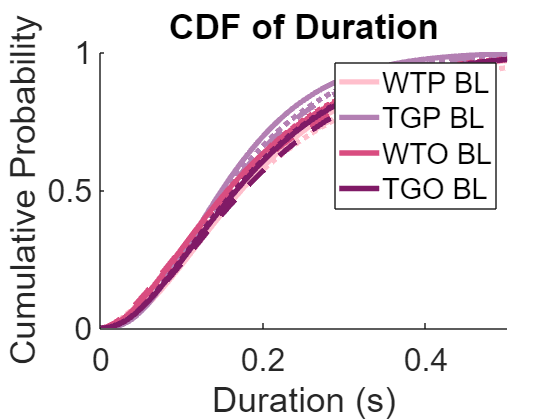

KS test results for Baseline (Duration):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0869
  WTP vs WTO: p = 0.0000, KS statistic = 0.0709
  WTP vs TGO: p = 0.0020, KS statistic = 0.0250
  TGP vs WTO: p = 0.0000, KS statistic = 0.0457
  TGP vs TGO: p = 0.0000, KS statistic = 0.0711
  WTO vs TGO: p = 0.0000, KS statistic = 0.0500


KS test results for Footshock (Duration):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0522
  WTP vs WTO: p = 0.0001, KS statistic = 0.0440
  WTP vs TGO: p = 0.0096, KS statistic = 0.0353
  TGP vs WTO: p = 0.0001, KS statistic = 0.0341
  TGP vs TGO: p = 0.0000, KS statistic = 0.0681
  WTO vs TGO: p = 0.0000, KS statistic = 0.0730


KS test results for Rest (Duration):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0632
  WTP vs WTO: p = 0.0000, KS statistic = 0.0389
  WTP vs TGO: p = 0.1476, KS statistic = 0.0157
  TGP vs WTO: p = 0.0000, KS statistic = 0.0441
  TGP vs TGO: p = 0.0000, KS statistic = 0.0549
  WTO vs TGO: p = 0.0000, KS statistic = 0.0421



Within-group KS test comparisons for parameter: Duration


Group: WTP


   BL vs. FS: p = 0.0424, KS statistic = 0.0288
   BL vs. rest: p = 0.0015, KS statistic = 0.0303
   FS vs. rest: p = 0.7229, KS statistic = 0.0144


Group: TGP


   BL vs. FS: p = 0.0031, KS statistic = 0.0271
   BL vs. rest: p = 0.1784, KS statistic = 0.0142
   FS vs. rest: p = 0.1993, KS statistic = 0.0168


Group: WTO


   BL vs. FS: p = 0.0235, KS statistic = 0.0168
   BL vs. rest: p = 0.0542, KS statistic = 0.0134
   FS vs. rest: p = 0.8646, KS statistic = 0.0068


Group: TGO


   BL vs. FS: p = 0.0001, KS statistic = 0.0328
   BL vs. rest: p = 0.4802, KS statistic = 0.0090
   FS vs. rest: p = 0.0000, KS statistic = 0.0363



Processing parameter: InterburstInterval


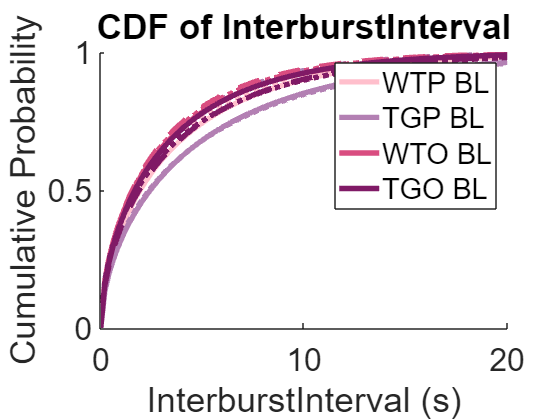

KS test results for Baseline (InterburstInterval):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0774
  WTP vs WTO: p = 0.0000, KS statistic = 0.0928
  WTP vs TGO: p = 0.0000, KS statistic = 0.0646
  TGP vs WTO: p = 0.0000, KS statistic = 0.1624
  TGP vs TGO: p = 0.0000, KS statistic = 0.1352
  WTO vs TGO: p = 0.0000, KS statistic = 0.0291


KS test results for Footshock (InterburstInterval):


  WTP vs TGP: p = 0.0008, KS statistic = 0.0426
  WTP vs WTO: p = 0.0000, KS statistic = 0.0657
  WTP vs TGO: p = 0.2130, KS statistic = 0.0231
  TGP vs WTO: p = 0.0000, KS statistic = 0.0866
  TGP vs TGO: p = 0.0091, KS statistic = 0.0295
  WTO vs TGO: p = 0.0000, KS statistic = 0.0605


KS test results for Rest (InterburstInterval):


  WTP vs TGP: p = 0.0000, KS statistic = 0.1046
  WTP vs WTO: p = 0.0000, KS statistic = 0.0341
  WTP vs TGO: p = 0.0069, KS statistic = 0.0233
  TGP vs WTO: p = 0.0000, KS statistic = 0.1335
  TGP vs TGO: p = 0.0000, KS statistic = 0.1224
  WTO vs TGO: p = 0.0249, KS statistic = 0.0158



Within-group KS test comparisons for parameter: InterburstInterval


Group: WTP


   BL vs. FS: p = 0.0281, KS statistic = 0.0306
   BL vs. rest: p = 0.0000, KS statistic = 0.0518
   FS vs. rest: p = 0.0463, KS statistic = 0.0287


Group: TGP


   BL vs. FS: p = 0.0000, KS statistic = 0.0842
   BL vs. rest: p = 0.0023, KS statistic = 0.0240
   FS vs. rest: p = 0.0000, KS statistic = 0.0644


Group: WTO


   BL vs. FS: p = 0.2223, KS statistic = 0.0119
   BL vs. rest: p = 0.0050, KS statistic = 0.0174
   FS vs. rest: p = 0.3199, KS statistic = 0.0109


Group: TGO


   BL vs. FS: p = 0.0000, KS statistic = 0.0416
   BL vs. rest: p = 0.2592, KS statistic = 0.0109
   FS vs. rest: p = 0.0000, KS statistic = 0.0451



Processing parameter: NumSpikes


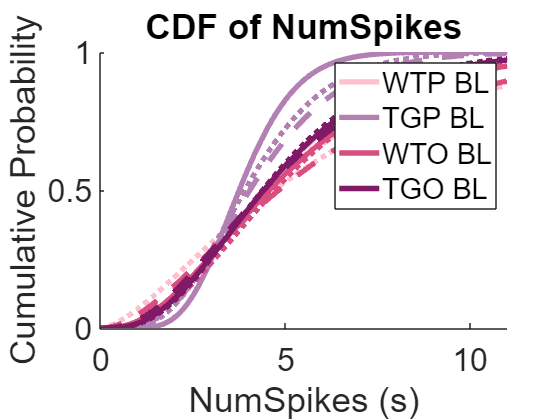

KS test results for Baseline (NumSpikes):


  WTP vs TGP: p = 0.0000, KS statistic = 0.1285
  WTP vs WTO: p = 0.0426, KS statistic = 0.0185
  WTP vs TGO: p = 0.6552, KS statistic = 0.0099
  TGP vs WTO: p = 0.0000, KS statistic = 0.1470
  TGP vs TGO: p = 0.0000, KS statistic = 0.1312
  WTO vs TGO: p = 0.0156, KS statistic = 0.0158


KS test results for Footshock (NumSpikes):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0770
  WTP vs WTO: p = 0.0001, KS statistic = 0.0430
  WTP vs TGO: p = 0.1617, KS statistic = 0.0242
  TGP vs WTO: p = 0.0000, KS statistic = 0.1155
  TGP vs TGO: p = 0.0000, KS statistic = 0.0615
  WTO vs TGO: p = 0.0000, KS statistic = 0.0548


KS test results for Rest (NumSpikes):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0997
  WTP vs WTO: p = 0.0000, KS statistic = 0.0616
  WTP vs TGO: p = 0.9280, KS statistic = 0.0075
  TGP vs WTO: p = 0.0000, KS statistic = 0.1600
  TGP vs TGO: p = 0.0000, KS statistic = 0.1069
  WTO vs TGO: p = 0.0000, KS statistic = 0.0559



Within-group KS test comparisons for parameter: NumSpikes


Group: WTP


   BL vs. FS: p = 0.9976, KS statistic = 0.0082
   BL vs. rest: p = 0.5594, KS statistic = 0.0126
   FS vs. rest: p = 0.8860, KS statistic = 0.0121


Group: TGP


   BL vs. FS: p = 0.0000, KS statistic = 0.0508
   BL vs. rest: p = 0.0053, KS statistic = 0.0223
   FS vs. rest: p = 0.0002, KS statistic = 0.0333


Group: WTO


   BL vs. FS: p = 0.0055, KS statistic = 0.0194
   BL vs. rest: p = 0.0000, KS statistic = 0.0318
   FS vs. rest: p = 0.0395, KS statistic = 0.0158


Group: TGO


   BL vs. FS: p = 0.0126, KS statistic = 0.0234
   BL vs. rest: p = 0.4371, KS statistic = 0.0094
   FS vs. rest: p = 0.2615, KS statistic = 0.0151



Processing parameter: FiringRate


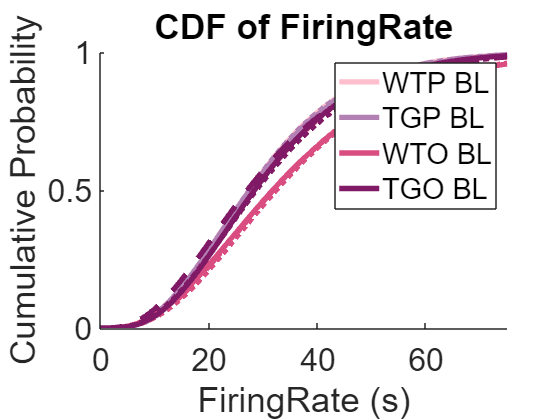

KS test results for Baseline (FiringRate):


  WTP vs TGP: p = 0.0007, KS statistic = 0.0285
  WTP vs WTO: p = 0.0000, KS statistic = 0.1149
  WTP vs TGO: p = 0.0000, KS statistic = 0.0325
  TGP vs WTO: p = 0.0000, KS statistic = 0.1271
  TGP vs TGO: p = 0.0000, KS statistic = 0.0493
  WTO vs TGO: p = 0.0000, KS statistic = 0.0877


KS test results for Footshock (FiringRate):


  WTP vs TGP: p = 0.1793, KS statistic = 0.0234
  WTP vs WTO: p = 0.0000, KS statistic = 0.1087
  WTP vs TGO: p = 0.0000, KS statistic = 0.0584
  TGP vs WTO: p = 0.0000, KS statistic = 0.1152
  TGP vs TGO: p = 0.0000, KS statistic = 0.0528
  WTO vs TGO: p = 0.0000, KS statistic = 0.1638


KS test results for Rest (FiringRate):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0365
  WTP vs WTO: p = 0.0000, KS statistic = 0.1257
  WTP vs TGO: p = 0.0163, KS statistic = 0.0213
  TGP vs WTO: p = 0.0000, KS statistic = 0.1592
  TGP vs TGO: p = 0.0000, KS statistic = 0.0452
  WTO vs TGO: p = 0.0000, KS statistic = 0.1207



Within-group KS test comparisons for parameter: FiringRate


Group: WTP


   BL vs. FS: p = 0.0067, KS statistic = 0.0350
   BL vs. rest: p = 0.0008, KS statistic = 0.0316
   FS vs. rest: p = 0.9167, KS statistic = 0.0115


Group: TGP


   BL vs. FS: p = 0.0000, KS statistic = 0.0367
   BL vs. rest: p = 0.1573, KS statistic = 0.0146
   FS vs. rest: p = 0.0029, KS statistic = 0.0282


Group: WTO


   BL vs. FS: p = 0.0565, KS statistic = 0.0151
   BL vs. rest: p = 0.0000, KS statistic = 0.0360
   FS vs. rest: p = 0.0000, KS statistic = 0.0286


Group: TGO


   BL vs. FS: p = 0.0000, KS statistic = 0.0725
   BL vs. rest: p = 0.1962, KS statistic = 0.0116
   FS vs. rest: p = 0.0000, KS statistic = 0.0700



Processing parameter: ISIinBurst


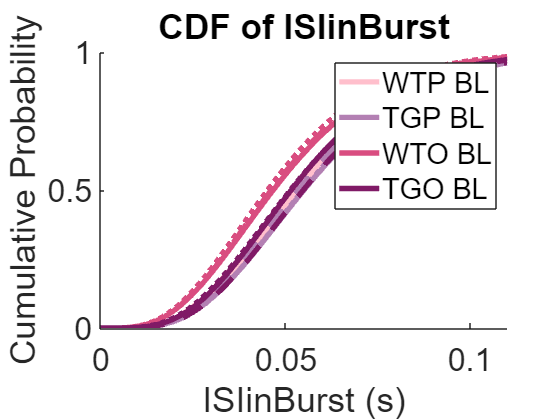

KS test results for Baseline (ISIinBurst):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0521
  WTP vs WTO: p = 0.0000, KS statistic = 0.1221
  WTP vs TGO: p = 0.0000, KS statistic = 0.0313
  TGP vs WTO: p = 0.0000, KS statistic = 0.1556
  TGP vs TGO: p = 0.0000, KS statistic = 0.0775
  WTO vs TGO: p = 0.0000, KS statistic = 0.0920


KS test results for Footshock (ISIinBurst):


  WTP vs TGP: p = 0.0083, KS statistic = 0.0353
  WTP vs WTO: p = 0.0000, KS statistic = 0.1145
  WTP vs TGO: p = 0.0000, KS statistic = 0.0659
  TGP vs WTO: p = 0.0000, KS statistic = 0.1427
  TGP vs TGO: p = 0.0004, KS statistic = 0.0367
  WTO vs TGO: p = 0.0000, KS statistic = 0.1756


KS test results for Rest (ISIinBurst):


  WTP vs TGP: p = 0.0000, KS statistic = 0.0558
  WTP vs WTO: p = 0.0000, KS statistic = 0.1358
  WTP vs TGO: p = 0.0178, KS statistic = 0.0211
  TGP vs WTO: p = 0.0000, KS statistic = 0.1883
  TGP vs TGO: p = 0.0000, KS statistic = 0.0695
  WTO vs TGO: p = 0.0000, KS statistic = 0.1327



Within-group KS test comparisons for parameter: ISIinBurst


Group: WTP


   BL vs. FS: p = 0.0147, KS statistic = 0.0325
   BL vs. rest: p = 0.0099, KS statistic = 0.0260
   FS vs. rest: p = 0.9699, KS statistic = 0.0102


Group: TGP


   BL vs. FS: p = 0.0000, KS statistic = 0.0432
   BL vs. rest: p = 0.0991, KS statistic = 0.0159
   FS vs. rest: p = 0.0001, KS statistic = 0.0359


Group: WTO


   BL vs. FS: p = 0.0022, KS statistic = 0.0208
   BL vs. rest: p = 0.0000, KS statistic = 0.0409
   FS vs. rest: p = 0.0000, KS statistic = 0.0284


Group: TGO


   BL vs. FS: p = 0.0000, KS statistic = 0.0706
   BL vs. rest: p = 0.1177, KS statistic = 0.0128
   FS vs. rest: p = 0.0000, KS statistic = 0.0676


% Define parameters and their axis settings
parameters = {'Duration', 'InterburstInterval', 'NumSpikes', 'FiringRate', 'ISIinBurst'};
axis_settings = struct( ...
    'Duration', struct('xlim', [0 0.5], 'ylim', [0 1], 'yticks', [0 0.5 1]), ...
    'InterburstInterval', struct('xlim', [0 20], 'ylim', [0 1], 'yticks', [0 0.5 1]), ...
    'NumSpikes', struct('xlim', [0 11], 'ylim', [0 1], 'yticks', [0 0.5 1]), ...
    'FiringRate', struct('xlim', [0 75], 'ylim', [0 1], 'yticks', [0 0.5 1]), ...
    'ISIinBurst', struct('xlim', [0 0.11], 'ylim', [0 1], 'yticks', [0 0.5 1]) ...
);

% Define colors for groups
groups = {'WTP', 'TGP', 'WTO', 'TGO'};
group_colors = [1 0.75 0.8;  % WTP - Light pink
                0.7 0.5 0.7;  % TGP - Purple
                0.85 0.3 0.5; % WTO - Reddish Pink
                0.5 0.1 0.4]; % TGO - Dark Purple

for p = 1:length(parameters)
    param = parameters{p};
    fprintf('\nProcessing parameter: %s\n', param);
    
    % Extract and filter data for the current parameter
    BL_data = cell(1, 4); % Store baseline data
    FS_data = cell(1, 4); % Store footshock data
    rest_data = cell(1,4);
    
    for g = 1:length(groups)
        group = groups{g};
        BL_data{g} = cleanedBlBursts.(param)(cleanedBlBursts.group == group);
        FS_data{g} = cleanedFsBursts.(param)(cleanedFsBursts.group == group);
        rest_data{g} = cleanedrestBursts.(param)(cleanedrestBursts.group == group);
        
        % Remove NaN or invalid values
        BL_data{g} = BL_data{g}(~isnan(BL_data{g}) & ~isinf(BL_data{g}));
        FS_data{g} = FS_data{g}(~isnan(FS_data{g}) & ~isinf(FS_data{g}));
        rest_data{g} = rest_data{g}(~isnan(rest_data{g}) & ~isinf(rest_data{g}));
    end
    
    % Fit Gamma distribution to valid groups
    params_BL = cell(1, 4);
    params_FS = cell(1, 4);
    params_rest = cell(1, 4);
    for g = 1:length(groups)
        if ~isempty(BL_data{g})
            params_BL{g} = gamfit(BL_data{g});
        end
        if ~isempty(FS_data{g})
            params_FS{g} = gamfit(FS_data{g});
        end
        if ~isempty(rest_data{g})
            params_rest{g} = gamfit(rest_data{g});
        end
    end
    
    % Define x values for Gamma CDF
    x = linspace(0, max(axis_settings.(param).xlim), 100);
    
    % Create figure
    figure;
    hold on;
    
    % Plot Gamma CDF for valid groups
    for g = 1:length(groups)
        if ~isempty(BL_data{g})
            BL_cdf = gamcdf(x, params_BL{g}(1), params_BL{g}(2));
            plot(x, BL_cdf, 'LineStyle', '-', 'LineWidth', 4, ...
                 'Color', group_colors(g, :), 'DisplayName', [groups{g}, ' BL']);
        end
        if ~isempty(FS_data{g})
            FS_cdf = gamcdf(x, params_FS{g}(1), params_FS{g}(2));
            plot(x, FS_cdf, 'LineStyle', '--', 'LineWidth', 4, ...
                 'Color', group_colors(g, :), 'HandleVisibility', 'off'); % Hides FS from legend
        end
        if ~isempty(rest_data{g})
            rest_cdf = gamcdf(x, params_rest{g}(1), params_rest{g}(2));
            plot(x, rest_cdf, 'LineStyle', ':', 'LineWidth', 4, ...
                 'Color', group_colors(g, :), 'HandleVisibility', 'off'); % Hides FS from legend
        end
    end
    
    % Apply axis settings and labels
    set(gca, 'FontSize', 24, 'FontName', 'Arial');
    xlabel([param ' (s)']);
    ylabel('Cumulative Probability');
    xlim(axis_settings.(param).xlim);
    ylim(axis_settings.(param).ylim);
    yticks(axis_settings.(param).yticks);
    title(['CDF of ', param]);
    
    % Ensure legend only shows BL
    legend('show');
    
    hold off;
   
    
    % --- Run Kolmogorov-Smirnov tests for baseline data ---
    fprintf('KS test results for Baseline (%s):\n', param);
    for i = 1:length(groups)
        for j = i+1:length(groups)
            % Perform KS test on baseline data from group i vs. group j
            [h, p_value, ksstat] = kstest2(BL_data{i}, BL_data{j});
            fprintf('  %s vs %s: p = %.4f, KS statistic = %.4f\n', groups{i}, groups{j}, p_value, ksstat);
        end
    end

   
    % For example, for FS data:
    fprintf('KS test results for Footshock (%s):\n', param);
    for i = 1:length(groups)
        for j = i+1:length(groups)
            [h, p_value, ksstat] = kstest2(FS_data{i}, FS_data{j});
            fprintf('  %s vs %s: p = %.4f, KS statistic = %.4f\n', groups{i}, groups{j}, p_value, ksstat);
        end
    end
    
    % And for rest data:
    fprintf('KS test results for Rest (%s):\n', param);
    for i = 1:length(groups)
        for j = i+1:length(groups)
            [h, p_value, ksstat] = kstest2(rest_data{i}, rest_data{j});
            fprintf('  %s vs %s: p = %.4f, KS statistic = %.4f\n', groups{i}, groups{j}, p_value, ksstat);
        end
    end

 fprintf('\nWithin-group KS test comparisons for parameter: %s\n', param);
    epochs = {'BL', 'FS', 'rest'};
    for g = 1:length(groups)
        fprintf('Group: %s\n', groups{g});
        for e1 = 1:length(epochs)
            for e2 = e1+1:length(epochs)
                % Select data for the first epoch
                switch epochs{e1}
                    case 'BL'
                        data1 = BL_data{g};
                    case 'FS'
                        data1 = FS_data{g};
                    case 'rest'
                        data1 = rest_data{g};
                end
                
                % Select data for the second epoch
                switch epochs{e2}
                    case 'BL'
                        data2 = BL_data{g};
                    case 'FS'
                        data2 = FS_data{g};
                    case 'rest'
                        data2 = rest_data{g};
                end
                
                if ~isempty(data1) && ~isempty(data2)
                    [h, p_value, ksstat] = kstest2(data1, data2);
                    fprintf('   %s vs. %s: p = %.4f, KS statistic = %.4f\n', epochs{e1}, epochs{e2}, p_value, ksstat);
                else
                    fprintf('   %s vs. %s: insufficient data\n', epochs{e1}, epochs{e2});
                end
            end
        end
    end



end

Representative Spike Trains

% Define colors for each group (matching reference image)
group_colors = [1 0.75 0.8;  % WTP - Light pink
                0.7 0.5 0.7;  % TGP - Purple
                0.85 0.3 0.5; % WTO - Reddish Pink
                0.5 0.1 0.4]; % TGO - Dark Purple

% Define sampling rate (1 ms resolution)
samplingRate = 1000; % Hz

% Create figure
figure; hold on;
trial_offset = 0;

for g = 1:length(groups)
    for e = 1:length(epochs)
        epoch = epochs{e};
        group = groups{g};

        % Get average burst properties
        if strcmp(epoch, 'BL')
            avg_duration = mean(cleanedBlBursts.Duration(cleanedBlBursts.group == group));
            avg_num_spikes = round(mean(cleanedBlBursts.NumSpikes(cleanedBlBursts.group == group)));
            avg_ISI = mean(cleanedBlBursts.ISIinBurst(cleanedBlBursts.group == group));
        elseif strcmp(epoch, 'FS')
            avg_duration = mean(cleanedFsBursts.Duration(cleanedFsBursts.group == group));
            avg_num_spikes = round(mean(cleanedFsBursts.NumSpikes(cleanedFsBursts.group == group)));
            avg_ISI = mean(cleanedFsBursts.ISIinBurst(cleanedFsBursts.group == group));
        else
            avg_duration = mean(cleanedrestBursts.Duration(cleanedrestBursts.group == group));
            avg_num_spikes = round(mean(cleanedrestBursts.NumSpikes(cleanedrestBursts.group == group)));
            avg_ISI = mean(cleanedrestBursts.ISIinBurst(cleanedrestBursts.group == group));
        end

        % Handle missing data
        if isnan(avg_duration) || isnan(avg_num_spikes) || isnan(avg_ISI) || avg_num_spikes < 1
            fprintf('Skipping %s - %s due to insufficient data\n', group, epoch);
            continue;
        end
        
        fprintf('Generating burst for %s - %s...\n', group, epoch);

        % Define burst start time to stagger bursts
        burst_start = 0.2 * g + 0.1 * e;

        % Generate ISIs with slight variability to simulate real bursting
        jitter_factor = 0.2; % Adds slight variability
        burst_ISIs = avg_ISI * (1 + jitter_factor * randn(1, avg_num_spikes));
        burst_ISIs = max(burst_ISIs, avg_ISI * 0.5); % Prevent negative/too-small ISIs

        % Generate spike times
        burst_spike_times = burst_start + cumsum(burst_ISIs);
        burst_spike_times = burst_spike_times(burst_spike_times <= (burst_start + avg_duration));

        % Store burst spike times
        synthetic_burst_trains.(group).(epoch) = burst_spike_times;

        % Plot raster with high-contrast colors
        plot(burst_spike_times, trial_offset + ones(size(burst_spike_times)), '|', ...
            'Color', group_colors(g, :), 'MarkerSize', 16, 'LineWidth', 3);
        
        % Offset trials for better spacing
        trial_offset = trial_offset + 2.5;
    end
end

Generating burst for WTP - BL...
Generating burst for WTP - FS...
Generating burst for WTP - rest...
Generating burst for TGP - BL...
Generating burst for TGP - FS...
Generating burst for TGP - rest...
Generating burst for WTO - BL...
Generating burst for WTO - FS...
Generating burst for WTO - rest...
Generating burst for TGO - BL...
Generating burst for TGO - FS...
Generating burst for TGO - rest...


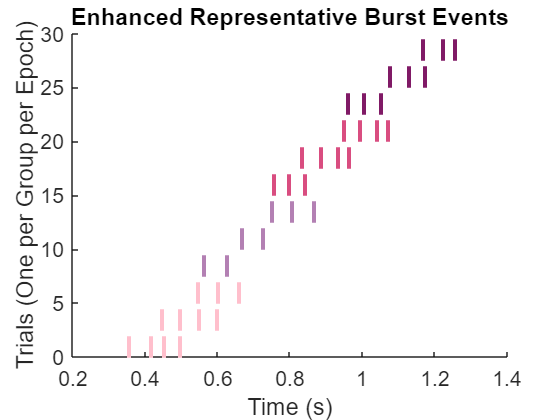


xlabel('Time (s)');
ylabel('Trials (One per Group per Epoch)');
title('Enhanced Representative Burst Events');
set(gca, 'FontSize', 16, 'FontName', 'Arial');

% Extract all non-empty burst spike times
all_spike_times = struct2cell(synthetic_burst_trains);
all_spike_times = all_spike_times(~cellfun(@isempty, all_spike_times)); % Remove empty entries

% Set x-axis limits
if isempty(all_spike_times)
    xlim([0, 0.2]); % Default limit if no data
else
    xlim([0, max(cellfun(@max, all_spike_times)) + 0.05]); % Use max spike time with buffer
end

Error using max
Invalid data type. First argument must be numeric or logical.


ylim([0, trial_offset + 1]);
hold off;




